clear all;
close all;
clc;

% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317', ...
%     'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174', ...
%     'tph574','tph574','tph574','tph578','tph578','tph578'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321', ...
%     '20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218', ...
%     '20250414','20250415','20250416','20250414','20250415','20250416'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving'};
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, Force 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = true; % true or false
% Kota_alignment = 0; %0: do not use, 1:use
% pullAlignFolderPath = 'E:\Nao_behavior\202504_CSHA\20250419_S1_combined';
% TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2, ...
%     0,0,0,0,0,0,0,0,0, ...
%     4,4,4,4,4,4}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504_CSHA';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];

% Animal = {'tph574','tph574','tph574','tph578','tph578','tph578'}; %'tph209';{'tph314'} %
% Date = {'20250414','20250415','20250416','20250414','20250415','20250416'}; % %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving'}; %heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, Force 
% state_action_value = false; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% Kota_alignment = 1; %0: do not use, 1:use
% pullAlignFolderPath = 'E:\Nao_behavior\202504\250414-16_roving_all_thres25\output';
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {4,4,4,4,4,4}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

window_size = 20; % イベントの前後で取得するタイムステップ数0; % イベントの前後で取得するタイムステップ数
force_thr = 25; 
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
exception_count = 0;
rng(1);

% calculate and plot state value

% Animal = {'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'}; %'tph209';{'tph314'} %
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715'}; %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching'}; %'heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, Force 
% state_action_value = true; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = false; % true or false
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202407';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];

% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317'}; %'tph209';{'tph314'} %
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321'}; % %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = false; % true or false
% Kota_alignment = 0; %0: do not use, 1:use
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\tph312_314_316_317_thres25\output';
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202403';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250420\'];

% Animal = {'tph578'}; %'tph199';'tph209'
% Date = {'20250514'}; %'20240414'; % '20230602';'20230827'
% % session_type = 'Value';
% totalTrial = 200; %150;
% Key = {''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = false; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% R_thres = 0.1; % Define your R-squared threshold here
% cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% % inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

% Animal = {'tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250514','20250516','20250518','20250520','20250514','20250516','20250518','20250520'}; %'20240414'; % '20230602';'20230827'
% % session_type = 'Value';
% totalTrial = 200; %150;
% Key = {'','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% R_thres = 0.10; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],...
%     [200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% % inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\251102_tph574_578\'];

% 25/07 S1 Yuzhe-san & Abo-kun data for multi animals
% Animal = {'C6J506','C6J506','C6J506'};
Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506'};
% Animal = {'tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506'}; %'tph199';'tph209'
% Date = {'20250725','20250730','20250801'};
Date = {'20250514','20250516','20250518','20250520','20250704','20250708','20250710','20250711','20250715','20250717','20250725','20250730','20250801'}; %'20240414'; % '20230602';'20230827'
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250703','20250704','20250707','20250708','20250709','20250710','20250711','20250714','20250715','20250716','20250717','20250718','20250723','20250724','20250725','20250728','20250729','20250730','20250731','20250801','20250804','20250805'};
% session_type = 'Value';
totalTrial = 200; %150;
Key = {'','','','','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
deconvolved = false;
sig_cell = false; %true;
clip = ''; %Trial, TrialStart, PullForce, PushForce 
state_action_value = false; % true or false
bayes = true; % true or false
layer = true; % true or false
test = false; % true or false
zscore_neuro = true;
decoder_SVM = true;
R_thres = 0.10; % Define your R-squared threshold here
cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]};
layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
    [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
    [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% Define the folder where the CSV files are located
pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {0,0,0};
image_reverse = {4,4,4,4,0,0,0,0,0,0,0,0,0};
% image_reverse = {4,4,4,4,4,4,4,4,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
data_parent_dir = 'E:\Nao_behavior\202506_Abo';
output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

% regularization = 'ridege'; % 'lasso'
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% output_parent_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/241025/'];
% data_parent_dir = '/media/naohiro/Volume/Nao_behavior/202403'; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% load ([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'])

% uniqueDateとuniqueAnimalを取得
uniqueDate = unique(Date);
uniqueAnimal = unique(Animal); 

% Outputパスのフォルダ名を生成
folder_name = [strrep(strjoin(uniqueAnimal),' ','_') '_GLM_push-pull_multi'];
% folder_name = [strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_GLM_state_value_multi'];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '/')
    output_dir = [output_dir '/'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

フォルダが作成されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_GLM_push-pull_multi/


% ファイル名を生成
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Dates = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.deconvolved = deconvolved;
params.sig_cell = sig_cell;
params.clip = clip;
params.state_action_value = state_action_value;
params.layer = layer;
params.test = test;
params.image_reverse = image_reverse;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_parent_dir = data_parent_dir;
params.force_thr = force_thr;
params.fps = fps;
params.before_event = before_event;
params.after_event = after_event;
params.exception_count = exception_count;
params.bayes = bayes;
params.window_size = window_size;
params.zscore = zscore_neuro;
params.decoder_SVM = decoder_SVM;
params.R_thres = R_thres;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

パラメータが保存されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501_C6J506_tph578_GLM_push-pull_multi/C6J501_C6J506_tph578_parameter.json


% if contains(Key{1},'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% all_global_acc_idx = global_acc_idx; %cell(1,length(Keys));
% % determine global_acc_idx
% for i_session = 1:length(Key)
%     cellset_num = cellset_nums{i_session};
%     cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %     local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
%     temp_global_acc_idx = table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'global_cell_index'));
%     all_global_acc_idx = intersect(all_global_acc_idx, temp_global_acc_idx);
% end

% if Kota_alignment == 1    
%     % Get a list of all CSV files in the folder
%     csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
% 
%     % Initialize an empty cell array to store the matrices
%     AlinmentTimingCells = {};
% 
%     % Loop through each CSV file and read the data
%     for k = 1:length(csvFiles)
%         % Get the full file name and read the CSV file
%         fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
%         data = table2array(readtable(fileName));
% 
%         % Store the data in the cell array
%         AlinmentTimingCells{k} = data;
%     end
% end

% load behavior data
data_folders = cell(1,length(Animal));
behavior_data = cell(1,length(Animal));
behavior_dec_data = cell(1,length(Animal));
neural_activity_data = cell(1,length(Animal));
neural_property_data = cell(1,length(Animal));
pointAreas_data = cell(1,length(Animal));
nan_time = cell(1,length(Animal));
behavior_cat_dec_data = cell(1,length(Animal));
trial_start_all = cell(1,length(Animal));
before_trial_start_act = cell(1,length(Animal)); 
after_trial_start_act = cell(1,length(Animal)); 
clip_idxs = cell(1,length(Animal)); 
clip_idxs_behavior = cell(1,length(Animal)); 
first_force_idx_all = cell(1, length(Animal));
before_initial_force_act = cell(1,length(Animal));
before_initial_force_act_mean = cell(1,length(Animal));
after_initial_force_act = cell(1,length(Animal));
after_initial_force_act_mean = cell(1,length(Animal));

for i_session = 1:length(Animal)
    if i_session <=4 %8 %temporal operation
       data_folders(i_session) = {['E:\Nao_behavior\202506' filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    else
       data_folders(i_session) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    end    
    % data_folders(i_session) = {[data_parent_dir filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    load([strjoin(data_folders(i_session)) filesep strjoin(Animal(i_session)) '_behavior_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);  
    % pushResistance = resistance_table.('pushResistance');
    % pullResistance = resistance_table.('pullResistance');
    trial_temp = behavior_neural_time(:,2);
    inside_trial_idx = [trial_temp ~= 0];  

    if strcmp(clip, 'Trial')
    %     behavior_data = behavior_neural_time_convolved_zscored_clip(:,2:size(behavior_neural_time_convolved_zscored_clip,2));
        behavior_data_session = behavior_neural_time_convolved_zscored_clip;
        clip_idxs{i_session} = inside_trial_idx;
        if bayes == true
            posterior = bayesian_neural_time_convolved_zscored_clip(:,1:14);
            prediction_error = bayesian_neural_time_convolved_zscored_clip(:,15:28);  
            behavior_data_session= [behavior_data_session posterior prediction_error];       
        elseif state_action_value == true
            state_value = state_value_neural_time_clip;
            action_value = action_value_neural_time_clip;
            behavior_data_session= [behavior_data_session state_value action_value];
        end
    else
        behavior_data_session = behavior_neural_time_convolved_zscored;
        if bayes == true
            posterior = bayesian_neural_time_convolved_zscored(:,1:14);
            prediction_error = bayesian_neural_time_convolved_zscored(:,15:28);    
            behavior_data_session= [behavior_data_session posterior prediction_error];  
        elseif state_action_value == true
            state_value = state_value_neural_time;
            action_value = action_value_neural_time;          
            behavior_data_session = [behavior_data_session state_value action_value];
        end
    end
    behavior_data_session_temp = behavior_data_session;
    % drop nan
    nan_time{i_session} = any(isnan(behavior_data_session),2);
    behavior_data_session(nan_time{i_session},:) = [];


    % if strcmp(clip, 'TrialStart')
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = [];
        % find index of each event
        trial_start_idx = transpose(find(trial_start == 1)); 
        temp_trial_start_idx = trial_start_idx;
        trial_start_idx_ori = trial_start_idx;
        valid_trial_start_idx = []; % 有効なインデックスを保存する配列を初期化
        % for i = 1:length(temp_trial_start_idx)
        %     if trial_start_idx(i)-fps*before_event<=0 | trial_start_idx(i)+fps*after_event>size(behavior_data,1)
        %         trial_start_idx = setdiff(trial_start_idx,temp_trial_start_idx(i));
        %         trial_start_idx_ori = setdiff(trial_start_idx_ori,temp_trial_start_idx(i));
        %         exception_count = exception_count + 1;
        %     else
        %         trial_start_idx = [trial_start_idx, temp_trial_start_idx(i)-fps*before_event:temp_trial_start_idx(i)+fps*after_event];
        %     end
        % end 
        for i = 1:length(temp_trial_start_idx)
            if trial_start_idx(i)-fps*before_event > 0 && trial_start_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_trial_start_idx = [valid_trial_start_idx, temp_trial_start_idx(i)-fps*before_event:temp_trial_start_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % エラーカウントの増加
            end
        end
        trial_start_idx = valid_trial_start_idx; % 有効なインデックスに更新
        
        % sort trial_start_idx and delete choufuku
        trial_start_idx = unique(sort(trial_start_idx));
    
    % elseif strcmp(clip, 'Force')
        force       = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = [];
        pull_force_idx       = find(force > force_thr);
        push_force_idx       = find(force < -force_thr);
        % only count first idx in 1 second
        temp_pull_force_idx = pull_force_idx(1);
        temp_push_force_idx = push_force_idx(1);
        for i = 2:length(pull_force_idx)
            if pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                temp_pull_force_idx(end+1) = pull_force_idx(i);
            end
        end
        for i = 2:length(push_force_idx)
            if push_force_idx(i) - temp_push_force_idx(end) >= fps
                temp_push_force_idx(end+1) = push_force_idx(i);
            end
        end        
        pull_force_idx = temp_pull_force_idx;
        pull_force_idx_ori = temp_pull_force_idx;
        valid_pull_force_idx = []; % 有効なインデックスを保存する配列を初期化
        for i = 1:length(temp_pull_force_idx)
            if pull_force_idx(i)-fps*before_event > 0 && pull_force_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_pull_force_idx = [valid_pull_force_idx, temp_pull_force_idx(i)-fps*before_event:temp_pull_force_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % エラーカウントの増加
            end
        end
        pull_force_idx = valid_pull_force_idx; % 有効なインデックスに更新        
        % sort force_idx and delete choufuku
        pull_force_idx = unique(sort(pull_force_idx));

        push_force_idx = temp_push_force_idx;
        push_force_idx_ori = temp_push_force_idx;
        valid_push_force_idx = []; % 有効なインデックスを保存する配列を初期化
        for i = 1:length(temp_push_force_idx)
            if push_force_idx(i)-fps*before_event > 0 && push_force_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_push_force_idx = [valid_push_force_idx, temp_push_force_idx(i)-fps*before_event:temp_push_force_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % エラーカウントの増加
            end
        end
        push_force_idx = valid_push_force_idx; % 有効なインデックスに更新        
        % sort force_idx and delete choufuku
        push_force_idx = unique(sort(push_force_idx));        
    
    if strcmp(clip, 'TrialStart')
        behavior_data_session = behavior_data_session(trial_start_idx,:);
        clip_idxs{i_session} = trial_start_idx;
    
    elseif strcmp(clip, 'PullForce')
        behavior_data_session = behavior_data_session(pull_force_idx,:);
        clip_idxs{i_session} = pull_force_idx;

    elseif strcmp(clip, 'PushForce')
        behavior_data_session = behavior_data_session(push_force_idx,:);
        clip_idxs{i_session} = push_force_idx;
    end    
    % preprocess to use undeconvolved behavior data and state and action value
    % of each taken state and action
    if strcmp(clip, 'Trial')
        if bayes == true
            pull_posterior_dec    = bayesian_neural_time(inside_trial_idx,9);
            push_posterior_dec    = bayesian_neural_time(inside_trial_idx,10);
            pull_neg_log_likelihood_dec    = bayesian_neural_time(inside_trial_idx,11); 
            push_neg_log_likelihood_dec    = bayesian_neural_time(inside_trial_idx,12); 
            behavior_dec_data_session = [behavior_neural_time(inside_trial_idx,:) bayesian_neural_time(inside_trial_idx,3:end)]; % pull_posterior_dec push_posterior_dec pull_neg_log_likelihood_dec push_neg_log_likelihood_dec];            
        elseif state_action_value == true
            state_value_dec  = state_value_neural_time_dec(inside_trial_idx);
            action_value_dec = action_value_neural_time_dec(inside_trial_idx);
            behavior_dec_data_session = [behavior_neural_time(inside_trial_idx,:) state_value_dec action_value_dec];
        else          
            behavior_dec_data_session = behavior_neural_time(inside_trial_idx,:);  
        end
        % --- 1. 元の時系列でイベントのインデックスを見つける ---

        % Trial Startのインデックス
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = []; % NaN除去
        original_trial_start_idx = find(trial_start == 1);

        % Forceのインデックス（1秒に1回の間引き処理も適用）
        force = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = []; % NaN除去
        original_pull_force_idx = find(force > force_thr);
        original_push_force_idx = find(force < -force_thr);

        % Pull Forceの間引き
        temp_pull_force_idx = [];
        if ~isempty(original_pull_force_idx)
            temp_pull_force_idx = original_pull_force_idx(1);
            for i = 2:length(original_pull_force_idx)
                if original_pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                    temp_pull_force_idx(end+1) = original_pull_force_idx(i);
                end
            end
        end
        original_pull_force_idx = temp_pull_force_idx;

        % Push Forceの間引き
        temp_push_force_idx = [];
        if ~isempty(original_push_force_idx)
            temp_push_force_idx = original_push_force_idx(1);
            for i = 2:length(original_push_force_idx)
                if original_push_force_idx(i) - temp_push_force_idx(end) >= fps
                    temp_push_force_idx(end+1) = original_push_force_idx(i);
                end
            end
        end
        original_push_force_idx = temp_push_force_idx;

        % --- 2. 元のインデックスをクリップ後の新しいインデックスに変換 ---
        
        % cumsumを使ってインデックスのマッピングを作成
        index_map = cumsum(inside_trial_idx);

        % Trial Startインデックスの変換
        is_start_in_trial = inside_trial_idx(original_trial_start_idx); % トライアル内に含まれるか判定
        valid_original_starts = original_trial_start_idx(is_start_in_trial);
        clipped_trial_start_idx = index_map(valid_original_starts);

        % Pull Forceインデックスの変換
        is_pull_in_trial = inside_trial_idx(original_pull_force_idx);
        valid_original_pulls = original_pull_force_idx(is_pull_in_trial);
        clipped_pull_force_idx = index_map(valid_original_pulls);
        
        % Push Forceインデックスの変換
        is_push_in_trial = inside_trial_idx(original_push_force_idx);
        valid_original_pushes = original_push_force_idx(is_push_in_trial);
        clipped_push_force_idx = index_map(valid_original_pushes);

        % --- 3. 結果を構造体にまとめて保存 ---
        clip_idxs_behavior{i_session} = struct(); % 構造体として初期化
        clip_idxs_behavior{i_session}.trial_start = clipped_trial_start_idx;
        clip_idxs_behavior{i_session}.pull_force = clipped_pull_force_idx;
        clip_idxs_behavior{i_session}.push_force = clipped_push_force_idx;        
    else
        if bayes == true
            pull_posterior_dec    = bayesian_neural_time(:,9);
            push_posterior_dec    = bayesian_neural_time(:,10);
            pull_neg_log_likelihood_dec    = bayesian_neural_time(:,11); 
            push_neg_log_likelihood_dec    = bayesian_neural_time(:,12);           
            behavior_dec_data_session = [behavior_neural_time bayesian_neural_time(:,3:end)]; %pull_posterior_dec push_posterior_dec pull_neg_log_likelihood_dec push_neg_log_likelihood_dec];            
        elseif state_action_value == true
            state_value_dec  = state_value_neural_time_dec;
            action_value_dec = action_value_neural_time_dec;
            behavior_dec_data_session = [behavior_neural_time state_value_dec action_value_dec];
        else
            behavior_dec_data_session = behavior_neural_time;
        end
        % Trial Startのインデックス
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = []; % NaN除去
        original_trial_start_idx = find(trial_start == 1);

        % Forceのインデックス（1秒に1回の間引き処理も適用）
        force = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = []; % NaN除去
        original_pull_force_idx = find(force > force_thr);
        original_push_force_idx = find(force < -force_thr);

        % Pull Forceの間引き
        temp_pull_force_idx = [];
        if ~isempty(original_pull_force_idx)
            temp_pull_force_idx = original_pull_force_idx(1);
            for i = 2:length(original_pull_force_idx)
                if original_pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                    temp_pull_force_idx(end+1) = original_pull_force_idx(i);
                end
            end
        end
        original_pull_force_idx = temp_pull_force_idx;

        % Push Forceの間引き
        temp_push_force_idx = [];
        if ~isempty(original_push_force_idx)
            temp_push_force_idx = original_push_force_idx(1);
            for i = 2:length(original_push_force_idx)
                if original_push_force_idx(i) - temp_push_force_idx(end) >= fps
                    temp_push_force_idx(end+1) = original_push_force_idx(i);
                end
            end
        end
        original_push_force_idx = temp_push_force_idx;  

        % --- 3. 結果を構造体にまとめて保存 ---
        clip_idxs_behavior{i_session} = struct(); % 構造体として初期化
        clip_idxs_behavior{i_session}.trial_start = original_trial_start_idx;
        clip_idxs_behavior{i_session}.pull_force = original_pull_force_idx;
        clip_idxs_behavior{i_session}.push_force = original_push_force_idx;
    end
    % behavior_dec_data_session_temp = behavior_dec_data_session;
    % drop nan
    dec_nan_time{i_session} = any(isnan(behavior_dec_data_session),2);
    behavior_dec_data_session(dec_nan_time{i_session},:) = [];   
    behavior_dec_data{i_session} = behavior_dec_data_session;        
    behavior_data{i_session} = behavior_data_session;

    trial_temp = behavior_neural_time(:,2);
    % resistance_temp = behavior_neural_time(:,5);
    trial_len = 200;
    trial_start_all_session = NaN(size(trial_len));  % 初期化：全てNaN
    trial_end_all_session = NaN(size(trial_len));  % 初期化：全てNaN
    
    % 0→非0への変化点を検出
    trial_diff = diff([0; trial_temp]);
    change_points = find(trial_diff ~= 0 & trial_temp ~= 0);  % 変化して0以外になった点
    
    % Decording of categorical value (Easy)
    resistance_table = readtable([strjoin(data_folders(i_session)) filesep 'resistance.csv']);
    pullResistance = resistance_table.('pullResistance'); % state1: 8 (light) or 16-64 (heavy)
    pushResistance = resistance_table.('pushResistance');
    trial = 1:length(pullResistance); %resistance_table.('trial#');

    % 各試行種別について最初の出現点を格納
    for trial_type = 1:length(pullResistance)
        idx = find(trial_temp(change_points) == trial_type, 1, 'first');
        if ~isempty(idx)
            trial_start_all_session(trial_type) = change_points(idx);  % 該当 trial_type に保存
        end
    end    
    trial_start_all{i_session} =  trial_start_all_session;
    % 各試行種別について最後の出現点を格納
    for trial_type = 1:length(pullResistance)
        idx = find(trial_temp == trial_type, 1, 'last');  % 最後の出現点
        if ~isempty(idx)
            trial_end_all_session(trial_type) = idx;
        end
    end
    trial_end_all{i_session}   = trial_end_all_session;

    % Categorical decoding analysis
    % % 1つ前の抵抗を記録
    % pushCorrectRate = resistance_table.('PushCorrectRate');
    % push_pull = resistance_table.('push-pull');
    choice_pred = pushCorrect;
    choice_correct = NaN(size(pushPull));
    choice_correct(pushPull == 687) = 1;
    choice_correct(pushPull == 657) = 0;
    choice_error = ((choice_correct == 1) & (choice_pred < 0.5)) | ((choice_correct == 0) & (choice_pred > 0.5));
    % 
    % % 抵抗値が前と違う場所を1とする
    % resistance_error = [0; resistance(2:end) ~= resistance(1:end-1)];
    
    % マウスがどちらの選択を行ったかのデコーディング
    trial_temp = behavior_neural_time(:,2);
    position_temp = behavior_neural_time(:,6);
    force_temp = behavior_neural_time(:,7);
    % --- 解析の準備 ---
    % 0やNaNを除いたユニークなトライアル番号を取得
    unique_trials = unique(trial_temp(trial_temp > 0 & ~isnan(trial_temp)));
    max_trial_num = max(unique_trials);
    
    % 結果を格納する配列をNaNで初期化
    % これにより、処理されなかったトライアルを後で確認できます
    first_choice = NaN(max_trial_num, 1);
    final_choice = NaN(max_trial_num, 1);

    % first_forceの「絶対インデックス」を保存する配列を初期化
    first_force_idx_session = NaN(max_trial_num, 1);

    % --- 各トライアルをループして選択を判定 ---
    for i = unique_trials' % unique_trialsの各要素でループ
        
        % 1. 現在のトライアル(i)に対応するインデックスを取得
        trial_indices = find(trial_temp == i);
        
        % 2. そのトライアルのpositionとforceデータを抽出
        % positionが動ききっていない場合に備えて1 step余分に追加
        i_position_temp = position_temp(trial_indices(1):trial_indices(end)+1);
        i_force_temp = force_temp(trial_indices);
        
        % --- final_choice (位置に基づく最終選択) の判定 ---
        % 位置が657を下回るか687を上回る最初のインデックスを検索
        idx_final = find(i_position_temp <= 657 | i_position_temp >= 687, 1, 'first');
        
        if isempty(idx_final)
            final_choice(i) = NaN; % 閾値に達しなかった場合
        else
            final_value = i_position_temp(idx_final);
            if final_value <= 657
                final_choice(i) = -1; % 657を下回った場合
            else % final_value >= 687
                final_choice(i) = 1;  % 687を上回った場合
            end
        end
        
        % --- first_choice (力に基づく最初の選択) の判定 ---
        % 力が-16を下回るか16を上回る最初のインデックスを検索
        idx_first = find(i_force_temp < -16 | i_force_temp > 16, 1, 'first');
        
        if isempty(idx_first)
            first_choice(i) = NaN; % 閾値に達しなかった場合
            first_force_idx_session(i) = NaN; % インデックスもNaN
        else
            % 1. 絶対インデックスを計算して保存
            absolute_force_idx = trial_indices(idx_first);
            first_force_idx_session(i) = absolute_force_idx;            
            first_value = i_force_temp(idx_first);
            if first_value < -16
                first_choice(i) = 1; % -16を下回った場合
            else % first_value > 16
                first_choice(i) = -1;  % 16を上回った場合
            end
        end
    end

    reward_amount = [];
    % pushRewardAmount = resistance_table.('pushRewardAmount');
    for i = 1:length(pullResistance)
        if pushPull(i) == 687
            reward_amount(end+1) = pushReward(i);
        elseif pushPull(i) == 657
            reward_amount(end+1) = 4 - pushReward(i);
        end
    end
    
    reward_amount = transpose(reward_amount);
    reward_pred = pushReward;  % 予測配列
    reward_error = (reward_amount == 1);
    
    % 予測と実際の不一致をエラーとして 1 にする
    % reward_error = double(reward_pred ~= reward_amount);  
    behavior_cat_dec_data_session = [choice_correct choice_pred choice_error reward_amount reward_pred reward_error first_choice final_choice];
    behavior_cat_dec_data{i_session} = behavior_cat_dec_data_session;

    % セッションの結果をメインのセル配列に格納
    first_force_idx_all{i_session} = first_force_idx_session;    
end

% load neural activity data

for i_session = 1:length(Animal)
    load([strjoin(data_folders(i_session)) filesep strjoin(Animal(i_session)) '_neural_activity_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);  
    % neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    if deconvolved ~= true
        % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);    
    %     neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
        neural_activity_data_session = acc_neural_activity_data;
        neural_property_data_session = acc_neural_property_data;
        pointAreas_data_session = pointAreas;
        % if sig_cell == true
        %     neural_activity_data_session = acc_neural_activity_data(:,find(sig_cell_idxs{4}==1)); % 4?
        %     neural_property_data_session = acc_neural_property_data(:,find(sig_cell_idxs{4}==1));
        %     pointAreas_data_session = pointAreas(:,find(sig_cell_idxs{4}==1));
        %     % trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
        % end
    %     neural_activity_data_ori = neural_activity_data;
        % drop nan
        
        if strcmp(clip, 'Trial')
            inside_trial_idx = clip_idxs{i_session};
            neural_activity_data_session = neural_activity_data_session(inside_trial_idx,:);
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            % neural_property_data_session = neural_property_data_session(inside_trial_idx,:);
            % pointAreas_data_session = pointAreas(inside_trial_idx,:);
        elseif strcmp(clip, 'TrialStart')
            trial_start_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(trial_start_idx,:);
            % neural_property_data_session = neural_property_data_session(trial_start_idx,:);
            % pointAreas_data_session = pointAreas(trial_start_idx,:);
        elseif strcmp(clip, 'PullForce')
            pull_force_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(pull_force_idx,:);
            % neural_property_data_session = neural_property_data_session(force_idx,:);
            % pointAreas_data_session = pointAreas(force_idx,:);
        elseif strcmp(clip, 'PushForce')
            push_force_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(push_force_idx,:);
            % neural_property_data_session = neural_property_data_session(force_idx,:);
            % pointAreas_data_session = pointAreas(force_idx,:);            
        else
            neural_activity_data_session(nan_time{i_session},:) = [];
        end       
    % else
    %     neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    %     neural_activity_event_table = readtable([data_folder filesep 'events.csv']);%,'NumHeaderLines',1); #Linux
    %     neural_activity_data = zeros(size(neural_activity_table,1),size(neural_activity_table,2)-1);
    %     for i = 1:size(neural_activity_event_table,1)
    %         differences = abs(table2array(neural_activity_table(:,'Var1')) - table2array(neural_activity_event_table(i,1)));
    %         [~, time_idx] = min(differences);
    % %         time_idx = find(table2array(neural_activity_table(:,'Var1')) == table2array(neural_activity_event_table(i,1)));
    %         numberStr = regexp(table2array(neural_activity_event_table(i,2)), '\d+', 'match', 'once');
    %         cell_idx = str2double(numberStr)+1; % shift 1 because cell idx start from 000
    %         neural_activity_data(time_idx,cell_idx) = table2array(neural_activity_event_table(i,3));
    %     end
    %     nonZeroCount = sum(neural_activity_data ~= 0, 1);
    %     columnsToRemove = nonZeroCount <= 30;
    %     neural_activity_data = neural_activity_data(:, ~columnsToRemove);
    %     % drop nan
    %     neural_activity_data(nan_time,:) = [];
    end
    neural_activity_data{i_session} = neural_activity_data_session;
    neural_property_data{i_session} = neural_property_data_session;
    pointAreas_data{i_session} = pointAreas_data_session;

% --- Initialize variables ---
    % For MEAN activity (original behavior)
    before_trial_start_act_mean_session = [];
    after_trial_start_act_mean_session  = [];
    before_trial_end_act_mean_session   = [];
    after_trial_end_act_mean_session    = [];
    
    % For ALL extracted activity (new behavior, using cell arrays)
    before_trial_start_act_session = {};
    after_trial_start_act_session  = {};
    before_trial_end_act_session   = {};
    after_trial_end_act_session    = {};

    before_initial_force_act_session = {};
    before_initial_force_act_mean_session = []; 
    after_initial_force_act_session = {};
    after_initial_force_act_mean_session = [];    

    % --- Loop through trials ---
    for i = 1:length(trial_start_all{i_session})
        %% ---------- trial start ----------
        idx_start = trial_start_all{i_session}(i);
    
        if ~isnan(idx_start)
            % Define windows
            before_start = max(1, idx_start - window_size);
            before_end   = idx_start - 1;
            after_start  = idx_start;
            after_end    = min(size(acc_neural_activity_data, 1), idx_start + window_size - 1);
    
            % Process BEFORE window
            if idx_start - window_size > 0 %before_end >= before_start
                % 1. Extract the full neural activity chunk
                before_chunk = acc_neural_activity_data(before_start:before_end, :);
                % 2. Calculate the mean of that chunk
                before_mean = mean(before_chunk, 1);
            else
                before_chunk = NaN(window_size, size(acc_neural_activity_data, 2)); % Store NaNs for consistency
                before_mean  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Process AFTER window
            if idx_start + window_size - 1 <= size(acc_neural_activity_data, 1) %after_end >= after_start
                % 1. Extract the full neural activity chunk
                after_chunk = acc_neural_activity_data(after_start:after_end, :);
                % 2. Calculate the mean of that chunk
                after_mean = mean(after_chunk, 1);
            else
                after_chunk = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Append results to respective variables
            before_trial_start_act_mean_session = [before_trial_start_act_mean_session; before_mean];
            after_trial_start_act_mean_session  = [after_trial_start_act_mean_session;  after_mean];
            before_trial_start_act_session{end+1} = before_chunk;
            after_trial_start_act_session{end+1}  = after_chunk;
        end
    
        %% ---------- trial end ----------
        idx_end = trial_end_all{i_session}(i);
    
        if ~isnan(idx_end)
            % Define windows
            before_start = max(1, idx_end - window_size);
            before_end   = idx_end - 1;
            after_start  = idx_end;
            after_end    = min(size(acc_neural_activity_data, 1), idx_end + window_size - 1);
    
            % Process BEFORE window
            if before_end >= before_start
                before_chunk_end = acc_neural_activity_data(before_start:before_end, :);
                before_mean_end  = mean(before_chunk_end, 1);
            else
                before_chunk_end = NaN(window_size, size(acc_neural_activity_data, 2));
                before_mean_end  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Process AFTER window
            if after_end >= after_start
                after_chunk_end = acc_neural_activity_data(after_start:after_end, :);
                after_mean_end  = mean(after_chunk_end, 1);
            else
                after_chunk_end = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean_end  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Append results to respective variables
            before_trial_end_act_mean_session = [before_trial_end_act_mean_session; before_mean_end];
            after_trial_end_act_mean_session  = [after_trial_end_act_mean_session;  after_mean_end];
            before_trial_end_act_session{end+1} = before_chunk_end;
            after_trial_end_act_session{end+1}  = after_chunk_end;
        end

        %% ---------- initial force ----------
        idx_force = first_force_idx_all{i_session}(i);

        if ~isnan(idx_force)
            % Define windows
            before_start_force = max(1, idx_force - window_size);
            before_end_force   = idx_force - 1;
            after_start_force  = idx_force;
            after_end_force    = min(size(acc_neural_activity_data, 1), idx_force + window_size - 1);            
    
            % Process BEFORE window (Robust NaN padding)
            if before_end_force >= 1
                available_chunk_force = acc_neural_activity_data(before_start_force:before_end_force, :);
                num_missing_rows_force = window_size - size(available_chunk_force, 1);
                
                if num_missing_rows_force > 0
                    nan_padding_force = NaN(num_missing_rows_force, size(acc_neural_activity_data, 2));
                    before_chunk_force = [nan_padding_force; available_chunk_force];
                else
                    before_chunk_force = available_chunk_force;
                end
                before_mean_force = mean(before_chunk_force, 1, 'omitnan');
            else
                before_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
                before_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            end

            % --- Process AFTER window (Robust NaN padding) ---
            if after_start_force <= size(acc_neural_activity_data, 1)
                available_chunk_after_force = acc_neural_activity_data(after_start_force:after_end_force, :);
                num_missing_rows_after_force = window_size - size(available_chunk_after_force, 1);
                
                if num_missing_rows_after_force > 0
                    nan_padding_after_force = NaN(num_missing_rows_after_force, size(acc_neural_activity_data, 2));
                    after_chunk_force = [available_chunk_after_force; nan_padding_after_force]; % Append NaNs at the end
                else
                    after_chunk_force = available_chunk_after_force;
                end
                after_mean_force = mean(after_chunk_force, 1, 'omitnan');
            else
                after_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            end

            % Append results to respective variables
            before_initial_force_act_mean_session = [before_initial_force_act_mean_session; before_mean_force];
            before_initial_force_act_session{end+1} = before_chunk_force;
            after_initial_force_act_mean_session = [after_initial_force_act_mean_session; after_mean_force];
            after_initial_force_act_session{end+1} = after_chunk_force;            
        else
            % Handle NaN index
            before_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
            before_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            after_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2)); 
            after_mean_force  = NaN(1, size(acc_neural_activity_data, 2));            
            
            before_initial_force_act_mean_session = [before_initial_force_act_mean_session; before_mean_force];
            before_initial_force_act_session{end+1} = before_chunk_force;
            after_initial_force_act_mean_session = [after_initial_force_act_mean_session; after_mean_force]; 
            after_initial_force_act_session{end+1} = after_chunk_force;            
        end        
    end

    % --- Save results for the current session ---
    % Save the full, un-averaged data chunks
    before_trial_start_act{i_session} = before_trial_start_act_session;
    after_trial_start_act{i_session}  = after_trial_start_act_session;
    before_trial_end_act{i_session}   = before_trial_end_act_session;
    after_trial_end_act{i_session}    = after_trial_end_act_session;
    
    % Save the mean-averaged data with a new name
    before_trial_start_act_mean{i_session} = before_trial_start_act_mean_session;
    after_trial_start_act_mean{i_session}  = after_trial_start_act_mean_session;
    before_trial_end_act_mean{i_session}   = before_trial_end_act_mean_session;
    after_trial_end_act_mean{i_session}    = after_trial_end_act_mean_session;   

    % 新しい変数を保存
    before_initial_force_act{i_session} = before_initial_force_act_session;
    before_initial_force_act_mean{i_session} = before_initial_force_act_mean_session;    
    after_initial_force_act{i_session} = after_initial_force_act_session;
    after_initial_force_act_mean{i_session} = after_initial_force_act_mean_session;
    % before_trial_start_act_session = [];before_trial_end_act_session = [];
    % after_trial_start_act_session = [];after_trial_end_act_session = [];
    % 
    % for i = 1:length(trial_start_all{i_session})
    %     %% ---------- trial start ----------
    %     idx_start = trial_start_all{i_session}(i);
    % 
    %     if ~isnan(idx_start)
    %         before_start = max(1, idx_start - window_size);
    %         before_end = idx_start - 1;
    %         after_start = idx_start;
    %         after_end = min(size(acc_neural_activity_data, 1), idx_start + window_size - 1);
    % 
    %         if before_end >= before_start
    %             before_mean = mean(acc_neural_activity_data(before_start:before_end, :), 1);
    %         else
    %             before_mean = NaN(1, size(acc_neural_activity_data, 2));
    %         end
    % 
    %         if after_end >= after_start
    %             after_mean = mean(acc_neural_activity_data(after_start:after_end, :), 1);
    %         else
    %             after_mean = NaN(1, size(acc_neural_activity_data, 2));
    %         end
    % 
    %         before_trial_start_act_session = [before_trial_start_act_session; before_mean];
    %         after_trial_start_act_session  = [after_trial_start_act_session;  after_mean];
    %     end
    % 
    %     %% ---------- trial end ----------
    %     idx_end = trial_end_all{i_session}(i);
    % 
    %     if ~isnan(idx_end)
    %         before_start = max(1, idx_end - window_size);
    %         before_end = idx_end - 1;
    %         after_start = idx_end;
    %         after_end = min(size(acc_neural_activity_data, 1), idx_end + window_size - 1);
    % 
    %         if before_end >= before_start
    %             before_mean_end = mean(acc_neural_activity_data(before_start:before_end, :), 1);
    %         else
    %             before_mean_end = NaN(1, size(acc_neural_activity_data, 2));
    %         end
    % 
    %         if after_end >= after_start
    %             after_mean_end = mean(acc_neural_activity_data(after_start:after_end, :), 1);
    %         else
    %             after_mean_end = NaN(1, size(acc_neural_activity_data, 2));
    %         end
    % 
    %         before_trial_end_act_session = [before_trial_end_act_session; before_mean_end];
    %         after_trial_end_act_session  = [after_trial_end_act_session;  after_mean_end];
    %     end
    % end
    % before_trial_start_act{i_session} = before_trial_start_act_session;
    % after_trial_start_act{i_session} = after_trial_start_act_session;
    % before_trial_end_act{i_session}   = before_trial_end_act_session;
    % after_trial_end_act{i_session}    = after_trial_end_act_session;
end

% % determine which layer each cell belong by cell position
% if categorize == 'layer'
% %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
% %     Inscopix imaging FOV
%     layer_bounds_pix = layer_bounds_um * (1280/4) /900; 
%     x_pix = [1; 100; 200];
%     % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
%     % TODO: have to be reverse y axis and x axis depending on the orientation of
%     % the image
%     if image_reverse == 0
%         neural_locations = [acc_neural_property_data(:,5), acc_neural_property_data(:,4)];
%     else
%         % reverse layer_bounds_pix
%         layer_bounds_pix = flip(layer_bounds_pix)
%         neural_locations = [1280/4 - acc_neural_property_data(:,5), acc_neural_property_data(:,4)];       
%     end
%     %reshape neural_locations to N*2
%     % combine x_pix and layer_bounds_pix to 3*2
%     linePoints = [x_pix, layer_bounds_pix];
%     % determine the layer each cell belong based on the matlab function
%     % TODO: have to check which is which 0: layer2/3, 1: layer5
%     pointAreas = classifyPoints(neural_locations, linePoints);
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
% end

% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);

% % drop nan
% nan_time = any(isnan(behavior_data),2);
% behavior_data(nan_time,:) = [];
% neural_activity_data(nan_time,:) = [];
% trial_start_idx = ;
% trial_start_idx_ori = ;
% force_idx = ;
% force_idx_ori = ;

% neural_activity_data{2}

% temporal processing of neural activity data
% have to change for real data (need to make all variables positive)
% processed_neural_activity_data = max((neural_activity_data + repmat(std(neural_activity_data),length(neural_activity_data),1))./repmat(std(neural_activity_data),length(neural_activity_data),1),zeros(size(neural_activity_data)))
% zscore_neuroがtrueの場合にのみ処理を実行
processed_neural_activity_data = neural_activity_data;

if zscore_neuro
    fprintf('Applying z-score normalization to neural data...\n');
    
    % --- NaNのチェックを追加 ---
    % cellfunを使って各セル内にNaNがあるか調べ、anyで全体の有無を確認
    has_nan = any(cellfun(@(x) any(isnan(x), 'all'), neural_activity_data));
    
    if has_nan
        warning('NaN values detected in neural_activity_data. Z-scoring will be performed by ignoring NaNs.');
    end
    
    for i = 1:numel(processed_neural_activity_data)
        % ★ 'omitnan'フラグを追加して、NaNを無視してz-scoreを計算
        processed_neural_activity_data{i} = zscore(processed_neural_activity_data{i}, 0, 'omitnan');
    end
end

Applying z-score normalization to neural data...


% behavior_data{2}

% % GLM: predict neural activity from convolved task variables
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),2);
% 
% for i_cell = 1:size(neural_activity_data,2)
%     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',1,'NumLambda',100); %,'CV',5,'NumLambda',100);
%     idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
%     mincoefs{i_cell,1} = find(GLM{i_cell,1}(:,idxLambdaMinDeviance));
%     idxLambda1SE = GLM{i_cell,2}.Index1SE;
%     mincoefs{i_cell,2} = find(GLM{i_cell,1}(:,idxLambda1SE));
% end

% rowSums = sum(neural_activity_data,2);
% sum(rowSums == 0)

% % divide training and test data 0.7:0.3
behavior_data_train = cell(1,length(Animal));
behavior_data_test  = cell(1,length(Animal));
processed_neural_activity_data_train = cell(1,length(Animal));
processed_neural_activity_data_test = cell(1,length(Animal));
behavior_dec_train = cell(1,length(Animal));
behavior_dec_test  = cell(1,length(Animal));
processed_dec_neural_activity_data_train = cell(1,length(Animal));
processed_dec_neural_activity_data_test = cell(1,length(Animal));
behavior_cat_dec_train = cell(1,length(Animal));
behavior_cat_dec_test  = cell(1,length(Animal));
% before_trial_start_act_train = cell(1,length(Animal));
% before_trial_start_act_test = cell(1,length(Animal));
% after_trial_start_act_train = cell(1,length(Animal));
% after_trial_start_act_test = cell(1,length(Animal));
% before_trial_end_act_train = cell(1,length(Animal));
% before_trial_end_act_test = cell(1,length(Animal));
% after_trial_end_act_train = cell(1,length(Animal));
% after_trial_end_act_test = cell(1,length(Animal));

if test == true
    for i_session = 1:length(Animal)
        behavior_data_session = behavior_data{i_session};
        % behavior_data_session = behavior_dec_data{i_session};
        processed_neural_activity_data_session = processed_neural_activity_data{i_session};
        idxTrain = zeros(size(behavior_data_session,1),1);
        idxTrain(1:ceil(0.7*size(behavior_data_session,1))) = 1;
        idxTest  = ones(size(behavior_data_session,1),1);
        idxTest(1:ceil(0.7*size(behavior_data_session,1))) = 0;
        idxTrain = logical(idxTrain); idxTest = logical(idxTest);
        behavior_data_train_session = behavior_data_session(idxTrain,:);
        processed_neural_activity_data_train_session = processed_neural_activity_data_session(idxTrain,:);
        behavior_data_test_session = behavior_data_session(idxTest,:);
        processed_neural_activity_data_test_session = processed_neural_activity_data_session(idxTest,:); 

        behavior_data_train{i_session} = behavior_data_train_session;       
        processed_neural_activity_data_train{i_session} = processed_neural_activity_data_train_session;
        behavior_data_test{i_session} = behavior_data_test_session;
        processed_neural_activity_data_test{i_session} = processed_neural_activity_data_test_session;

        behavior_dec_data_session = behavior_dec_data{i_session};
        idx_dec_Train = zeros(size(behavior_dec_data_session,1),1);
        idx_dec_Train(1:ceil(0.7*size(behavior_dec_data_session,1))) = 1;
        idx_dec_Test  = ones(size(behavior_dec_data_session,1),1);
        idx_dec_Test(1:ceil(0.7*size(behavior_dec_data_session,1))) = 0;
        idx_dec_Train = logical(idx_dec_Train); idx_dec_Test = logical(idx_dec_Test);         
        behavior_dec_train_session = behavior_dec_data_session(idx_dec_Train,:);
        behavior_dec_test_session  = behavior_dec_data_session(idx_dec_Test,:);
        % standarize input and output
        behavior_dec_train_session = zscore_columns(behavior_dec_train_session);
        behavior_dec_test_session  = zscore_columns(behavior_dec_test_session); 

        behavior_dec_train{i_session} = behavior_dec_train_session;
        behavior_dec_test{i_session}  = behavior_dec_test_session; 

        processed_dec_neural_activity_data_train_session = processed_neural_activity_data_session(idx_dec_Train,:);
        processed_dec_neural_activity_data_test_session = processed_neural_activity_data_session(idx_dec_Test,:); 
        processed_dec_neural_activity_data_train{i_session} = processed_dec_neural_activity_data_train_session;
        processed_dec_neural_activity_data_test{i_session} = processed_dec_neural_activity_data_test_session;


        idxTrainTrial = zeros(size(behavior_cat_dec_data_session,1),1);
        idxTrainTrial(1:ceil(0.7*size(behavior_cat_dec_data_session,1))) = 1;
        idxTestTrial  = ones(size(behavior_cat_dec_data_session,1),1);
        idxTestTrial(1:ceil(0.7*size(behavior_cat_dec_data_session,1))) = 0;
        idxTrainTrial = logical(idxTrainTrial); idxTestTrial = logical(idxTestTrial);
        behavior_cat_dec_data_session = behavior_cat_dec_data{i_session};
        behavior_cat_dec_train_session = behavior_cat_dec_data_session(idxTrainTrial,:);
        behavior_cat_dec_test_session  = behavior_cat_dec_data_session(idxTestTrial,:);

        behavior_cat_dec_train{i_session} = behavior_cat_dec_train_session;
        behavior_cat_dec_test{i_session}  = behavior_cat_dec_test_session; 

        % before_trial_start_act_session = before_trial_start_act{i_session};
        % before_trial_start_act_train_session = before_trial_start_act_session(idxTrainTrial,:);
        % before_trial_start_act_test_session  = before_trial_start_act_session(idxTestTrial,:);
        % before_trial_start_act_train{i_session} = before_trial_start_act_train_session;
        % before_trial_start_act_test{i_session}  = before_trial_start_act_test_session;  
        % 
        % after_trial_start_act_session = after_trial_start_act{i_session};
        % after_trial_start_act_train_session = after_trial_start_act_session(idxTrainTrial,:);
        % after_trial_start_act_test_session  = after_trial_start_act_session(idxTestTrial,:);
        % after_trial_start_act_train{i_session} = after_trial_start_act_train_session;
        % after_trial_start_act_test{i_session}  = after_trial_start_act_test_session;   
        % 
        % before_trial_end_act_session = before_trial_end_act{i_session};
        % before_trial_end_act_train_session = before_trial_end_act_session(idxTrainTrial, :);
        % before_trial_end_act_test_session  = before_trial_end_act_session(idxTestTrial, :);
        % before_trial_end_act_train{i_session} = before_trial_end_act_train_session;
        % before_trial_end_act_test{i_session}  = before_trial_end_act_test_session;
        % 
        % after_trial_end_act_session = after_trial_end_act{i_session};
        % after_trial_end_act_train_session = after_trial_end_act_session(idxTrainTrial, :);
        % after_trial_end_act_test_session  = after_trial_end_act_session(idxTestTrial, :);
        % after_trial_end_act_train{i_session} = after_trial_end_act_train_session;
        % after_trial_end_act_test{i_session}  = after_trial_end_act_test_session;
    end
end

% rng default
% c = cvpartition(behavior_data(:,1),'Holdout',0.3);
% idxTrain = training(c,1);
% idxTest = ~idxTrain;
% behavior_data_train = behavior_data(idxTrain,:);
% processed_neural_activity_data_train = processed_neural_activity_data(idxTrain,:);
% behavior_data_test = behavior_data(idxTest,:);
% processed_neural_activity_data_test = processed_neural_activity_data(idxTest,:);

% linear decoding analysis
seed_num = 1;
l23_Rs = cell(1,length(Animal));
l5_Rs  = cell(1,length(Animal));

for i_session = 1:length(Animal)  
    standarized_neural_activity_data_train = zscore_columns(processed_dec_neural_activity_data_train{i_session});
    standarized_neural_activity_data_test  = zscore_columns(processed_dec_neural_activity_data_test{i_session});
    layer23_cells_train = processed_dec_neural_activity_data_train{i_session}(:,find(pointAreas_data{i_session} == 1));
    layer5_cells_train  = processed_dec_neural_activity_data_train{i_session}(:,find(pointAreas_data{i_session} == 0));
    layer23_cells_test  = processed_dec_neural_activity_data_test{i_session}(:,find(pointAreas_data{i_session} == 1));
    layer5_cells_test   = processed_dec_neural_activity_data_test{i_session}(:,find(pointAreas_data{i_session} == 0));
    num_vars = size(behavior_dec_train{i_session}, 2);
    l23_Rs_session = zeros(5, seed_num, num_vars);
    l5_Rs_session  = zeros(5, seed_num, num_vars);
    % l23_Rs_session = zeros(5,seed_num,13); % 13; variable num of behavior and Bayes related
    % l5_Rs_session = zeros(5,seed_num,13);
    for k_cells = 1:5
        for j_seed = 1:seed_num %:10
            rng(j_seed);
            
            try
                layer23_idx = randperm(size(layer23_cells_train,2),2^(k_cells+2));
                layer23_train = layer23_cells_train(:,layer23_idx);
                layer23_test  = layer23_cells_test(:,layer23_idx);
            catch
                layer23_idx = [];
                layer23_train = NaN;
                layer23_test = NaN;
                l23_Rs_session(k_cells,j_seed,:) = NaN; % layer23にNaNを代入
            end
            
            try
                layer5_idx  = randperm(size(layer5_cells_train,2),2^(k_cells+2));
                layer5_train  = layer5_cells_train(:,layer5_idx);
                layer5_test   = layer5_cells_test(:,layer5_idx);
            catch
                layer5_idx = [];
                layer5_train = NaN;
                layer5_test = NaN;
                l5_Rs_session(k_cells,j_seed,:)  = NaN; % layer5にNaNを代入
            end
            
            % % preprocess to use undeconvolved behavior data and state and action value
            % % of each taken state and action
            % state_value_dec  = state_value_neural_time_dec;
            % action_value_dec = action_value_neural_time_dec;
            % behavior_dec_data = [behavior_neural_time state_value_dec action_value_dec];
            % % drop nan
            % behavior_dec_data(nan_time,:) = [];
            % behavior_dec_train = behavior_dec_data(idxTrain,:);
            % behavior_dec_test  = behavior_dec_data(idxTest,:);
            % % standarize input and output
            % behavior_dec_train = zscore_columns(behavior_dec_train);
            % behavior_dec_test  = zscore_columns(behavior_dec_test);
            behavior_dec_train_session = behavior_dec_train{i_session};
            behavior_dec_test_session = behavior_dec_test{i_session};
            
            % construct linear decoder to predict behavior and task variables
            if ~isempty(layer23_idx)
                for i_beh_val = 1:size(behavior_dec_train_session,2)
                    layer23_model = ridge(behavior_dec_train_session(:,i_beh_val),layer23_train,0.01,0);
                    layer23_ypred = layer23_model(1) + layer23_test*layer23_model(2:end);
                    [~, ~, l23_R] = regression_accuracy(behavior_dec_test_session(:,i_beh_val),layer23_ypred);
                    l23_Rs_session(k_cells,j_seed,i_beh_val) = l23_R;
                end
            end
            
            if ~isempty(layer5_idx)
                for i_beh_val = 1:size(behavior_dec_train_session,2)
                    layer5_model  = ridge(behavior_dec_train_session(:,i_beh_val),layer5_train,0.01,0);
                    layer5_ypred  = layer5_model(1) + layer5_test*layer5_model(2:end);
                    [~, ~, l5_R]  = regression_accuracy(behavior_dec_test_session(:,i_beh_val),layer5_ypred);
                    l5_Rs_session(k_cells,j_seed,i_beh_val)  = l5_R;
                end
            end
        end
    end
    l23_Rs{i_session} = l23_Rs_session;    
    l5_Rs{i_session} = l5_Rs_session; 
end

Index in position 2 exceeds array bounds.

size(l23_Rs{1})
% l23_state_value_R_std
% l5_state_value_R_std

% plot decoding results
if bayes == true
    titles = {'Trial start', 'Trial end', 'Resistance', 'Position', 'Force', 'Reward', 'licking',...
        'Pull Resistance','Push Resistance','Pull obs.','Push obs.','Pull likelihood','Push likelihood','Pull posterior','Push posterior','Pull prediction error','Push prediction error'}; 
elseif state_action_value == true
    titles = {'Trial start', 'Trial end', 'Pull Resistance', 'Push Resistance', 'Position', 'Force', 'Reward', 'licking','V(s)','Q(s,a)'};
else
    titles = {'Trial start', 'Trial end', 'Pull Resistance', 'Push Resistance', 'Position', 'Force', 'Reward', 'licking'};  
end
for i = 1:length(titles)
    % Collect data from all cell arrays
    l23_data = [];
    l5_data = [];
    for k = 1:length(Animal) 
        l23_data = cat(2, l23_data, l23_Rs{k}(:,:,i+2)); % (条件数 x 繰り返し数) を繰り返し方向に結合
        l5_data = cat(2, l5_data, l5_Rs{k}(:,:,i+2));
    end
    % 平均と標準偏差を計算
    i_l23_R = nanmean(l23_data, 2);
    i_l23_R_std = nanstd(l23_data, 0, 2);
    i_l5_R = nanmean(l5_data, 2);
    i_l5_R_std = nanstd(l5_data, 0, 2);
    
    figure
    x = [8,16,32,64,128];
    hold on;
    errorbar(x,i_l23_R,i_l23_R_std,'-o','Color','g','LineWidth',1.5,'MarkerSize',8);
    errorbar(x,i_l5_R,i_l5_R_std,'-o','Color','b','LineWidth',1.5,'MarkerSize',8);
    set(gca,'Xscale','log');
    title([titles{i}]);
    hold off;
    legend({'layer23','layer5'},'Location','northwest');
    xlabel('Number of cells');
    ylabel('Decoding accuracy (r)');
    filename = [output_dir titles{i} '_decoding_accuracy.png'];    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_decoding_accuracy.png'];
    saveas(gcf,filename);
end

% % Statistical test
% % Two-way ANOVA posthoc Tukey
% 
% for i = 1:length(titles)
%     if i == 3
%         continue;
%     end
%     % Collect data from all cell arrays
%     l23_data = [];
%     l5_data = [];
%     for k = 1:length(Animal)
%         l23_data = cat(2, l23_data, l23_Rs{k}(:,:,i+2)); % (条件数 x 繰り返し数) を繰り返し方向に結合
%         l5_data = cat(2, l5_data, l5_Rs{k}(:,:,i+2));
%     end
%     % データを整形
%     l23_data_t = l23_data';
%     l5_data_t = l5_data';
%     data = [l23_data_t; l5_data_t]; % (繰り返し数 x 条件数)
%     data_vector = data(:); % ベクトル化
% 
%     % 因子を作成
%     num_repeats = size(l23_data_t,1); % 繰り返し数
%     num_conditions = size(l23_data_t,2); % 条件数
%     total_samples = num_repeats * 2 * num_conditions; % 合計サンプル数
% 
%     factor1 = [repmat({'L23'}, num_repeats,num_conditions); repmat({'L5'}, num_repeats,num_conditions)];
%     factor2_labels = {'8cells','16cells','32cells','64cells','128cells'};
%     factor2_per_repeat = repmat(factor2_labels, num_repeats,1);
%     factor2 = [factor2_per_repeat; factor2_per_repeat];
%     factor1 = factor1(:); factor2 = factor2(:);
% 
%     % NaNを含むエントリを削除
%     valid_idx = ~isnan(data_vector);
%     data_vector = data_vector(valid_idx);
%     factor1 = factor1(valid_idx);
%     factor2 = factor2(valid_idx);
% 
%     % グループごとの平均と分散を計算
%     [group_mean, group_std, group_names] = grpstats(data_vector, {factor1, factor2}, {'mean', 'std','gname'});
% 
%     % 結果をテーブルにまとめる
%     stats_table = table;
%     stats_table.Layer = group_names(:,1);
%     stats_table.Num_of_Cells = group_names(:,2);
%     stats_table.Mean = group_mean(:);
%     stats_table.Standard_Deviation = group_std(:);
% 
%     combined_factors = strcat(factor1,'_', factor2);  % factor1とfactor2を結合して新しいカテゴリ変数を作成
%     % Kruskal-Wallis 検定を実行
%     % Dunnの多重比較を実行
%     [p, tbl, stats] = kruskalwallis(data_vector, combined_factors, 'off');
%     [c, m, h, nms] = multcompare(stats, 'CType', 'dunn-sidak');
%     % [p, tbl, stats] = anovan(data_vector, {factor1, factor2}, 'varnames', {'layer','num_of_cells'}, 'display', 'off');
%     % [c, m, h, nms]  = multcompare(stats, 'dimension', [1,2], 'display', 'off');
% 
%     disp(titles{i});
%     disp('Group Statistics (Mean and STD):');
%     disp(stats_table);
%     disp('Kruskal-Wallis:');
%     disp(tbl);
%     disp('dunn-sidak multi comparison:');
%     tbl2 = array2table(c,"VariableNames",["Group1","Group2","Lower Limit","A-B","Upper Limit","P-value"]);
%     tbl2.("Group1")=nms(tbl2.("Group1"));
%     tbl2.("Group2")=nms(tbl2.("Group2"));
%     disp(tbl2);
%     ANOVA_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_ANOVA.csv'];
%     writecell(tbl, ANOVA_filename);
%     Tukey_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_Tukey.csv'];
%     writetable(tbl2, Tukey_filename);
% 
%     % グループ統計をCSVファイルに保存
%     stats_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_GroupStats.csv'];
%     writetable(stats_table, stats_filename);
% end

% % 可視化対象のセッション・細胞数・seed を選択
% i_session = 1;
% k_cells = 2;   % 例：2^5 = 32細胞
% j_seed = 1;
% 
% % 再現可能なランダム選択（layer5）
% rng(j_seed);
% layer5_idx = randperm(size(layer5_cells_train,2), 2^(k_cells+2));
% layer5_train = layer5_cells_train(:, layer5_idx);
% layer5_test  = layer5_cells_test(:, layer5_idx);
% 
% % テスト用行動変数データ
% true_behavior_all = behavior_dec_test{i_session};
% train_behavior_all = behavior_dec_train{i_session};
% 
% % 行動変数の数
% n_behaviors = size(true_behavior_all, 2);
% 
% % 図を作成
% figure('Position', [100, 100, 1400, 300 + 250*ceil(n_behaviors/2)]);
% t = 1:size(true_behavior_all, 1);  % 時間軸
% 
% for i_beh_val = 1:n_behaviors-2
%     % モデル構築と予測
%     layer5_model = ridge(train_behavior_all(:, i_beh_val), layer5_train, 0.01, 0);
%     layer5_ypred = layer5_model(1) + layer5_test * layer5_model(2:end);
%     true_behavior = true_behavior_all(:, i_beh_val);
% 
%     % subplot にプロット
%     subplot(ceil(n_behaviors/2), 2, i_beh_val);
%     plot(t, true_behavior, 'k', 'LineWidth', 1.2); hold on;
%     plot(t, layer5_ypred, 'r--', 'LineWidth', 1.2);
%     xlabel('Time (frame)');
%     ylabel(sprintf('Var %d', i_beh_val));
%     title(sprintf('Behavior %d (Layer 5, %d cells)', i_beh_val, 2^(k_cells+2)));
%     legend('True', 'Predicted');
% end
% 
% sgtitle(sprintf('Layer 5 - Behavior Prediction (Session %d, Seed %d, %d cells)', ...
%     i_session, j_seed, 2^(k_cells+2)));

% パラメータ
n_neurons_list = [8, 16, 32, 64];
num_animals = length(Animal);
num_folds = 10;

if decoder_SVM
    template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
else
    template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
end

% --- 結果を格納するための構造体を初期化 ---
results = struct();
trial_group_names = {'all_valid', 'straight', 'corrected'};
label_names = {'choice_correct', 'choice_pred', 'choice_error', 'reward_amount', 'reward_pred', 'reward_error', 'first_choice', 'final_choice'};

% --- メインループ ---
for i_animal = 1:num_animals
    
    fprintf('\n--- Processing Animal %d of %d ---\n', i_animal, num_animals);
    
    % --- 1. 事前に全ての3Dデータを作成 ---
    before_start_3d = cat(3, before_trial_start_act{i_animal}{2:end-1});
    after_start_3d  = cat(3, after_trial_start_act{i_animal}{2:end-1});
    before_end_3d   = cat(3, before_trial_end_act{i_animal}{2:end-1});
    before_force_3d = cat(3, before_initial_force_act{i_animal}{2:end-1});
    after_force_3d  = cat(3, after_initial_force_act{i_animal}{2:end-1});
    
    % --- 2. デコード対象のラベルと試行グループを定義 ---
    labels_to_decode = [1, 2, 7, 8];
    
    % 試行グループのインデックスを作成
    all_labels_raw = behavior_cat_dec_data{i_animal}(2:end-1, :);
    straight_trials_mask = (all_labels_raw(:,7) == all_labels_raw(:,8));
    corrected_trials_mask = (all_labels_raw(:,7) ~= all_labels_raw(:,8));
    
    trial_group_masks = {true(size(all_labels_raw,1),1), straight_trials_mask, corrected_trials_mask};
    
    % ニューロンの層情報を取得
    pointAreas = pointAreas_data{i_animal};
    l23_idx_all = find(pointAreas == 1);
    l5_idx_all  = find(pointAreas == 0);

    % --- 3. ネストしたループで各条件のデコーディングを実行 ---
    for i_group = 1:length(trial_group_names)
        current_group_name = trial_group_names{i_group};
        
        for j_label_val = labels_to_decode
            current_label_name = label_names{j_label_val};
            
            fprintf('  Group: %s, Label: %s\n', current_group_name, current_label_name);

            % a. ラベルに応じて使用する神経活動データを選択
            switch j_label_val
                case 1 % choice_correct
                    neural_data_3d = after_start_3d;
                case 2      % choice_pred
                    neural_data_3d = before_start_3d;
                case 7 % first_choice
                    neural_data_3d = before_force_3d; 
                    % neural_data_3d = after_start_3d;                    
                case 8      % final_choice
                    neural_data_3d = after_force_3d;
                    % neural_data_3d = before_end_3d;
            end
            
            % b. ラベルデータとNaNマスクを作成
            labels_raw = all_labels_raw(:, j_label_val);
            nan_mask = isnan(labels_raw);
            
            % c. 現在の試行グループとNaNマスクを組み合わせて最終的なインデックスを決定
            final_trial_mask = trial_group_masks{i_group} & ~nan_mask;
            
            % d. 最終的なインデックスでデータとラベルをフィルタリング
            labels_final = labels_raw(final_trial_mask);
            data_final_3d = neural_data_3d(:, :, final_trial_mask);
            
            % 有効な試行がなければスキップ
            if isempty(labels_final) || length(unique(labels_final)) < 2
                fprintf('    -> Skipping, not enough valid trials or classes.\n');
                continue;
            end
            
            % e. 補助関数を呼び出してデコーディングを実行
            rng_seed_offset = j_label_val*10 + i_animal*100 + i_group*1000;
            
            [acc_l23, f1_l23] = run_decoding(data_final_3d, labels_final, l23_idx_all, n_neurons_list, template, num_folds, rng_seed_offset);
            [acc_l5,  f1_l5]  = run_decoding(data_final_3d, labels_final, l5_idx_all,  n_neurons_list, template, num_folds, rng_seed_offset + 500);
            
            % f. 結果を構造体に保存
            results(i_animal).L23.(current_group_name).(current_label_name).accuracy = acc_l23;
            results(i_animal).L23.(current_group_name).(current_label_name).f1_score = f1_l23;
            results(i_animal).L5.(current_group_name).(current_label_name).accuracy = acc_l5;
            results(i_animal).L5.(current_group_name).(current_label_name).f1_score = f1_l5;
        end
    end
end

fprintf('\n--- Decoding analysis complete. ---\n');

% % パラメータ
% n_neurons_list = [8, 16, 32, 64]; %, 128];
% num_animals = length(Animal);
% num_labels = 8;
% num_folds = 10;
% 
% if decoder_SVM
%     template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
% else
%     template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
% end
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% f1_l23_before = cell(num_labels, num_animals);
% f1_l5_before  = cell(num_labels, num_animals);
% f1_l23_after  = cell(num_labels, num_animals);
% f1_l5_after   = cell(num_labels, num_animals);
% 
% % behavior_cat_dec_data_session = [choice_correct choice_pred choice_error reward_amount reward_pred reward_error first_choice final_choice];
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % --- 1. データを3次元行列に変換 (タイムステップ x ニューロン x 試行) ---
%         % 'cat(3, cell_array{:})' でセル配列を3次元目に連結
%         % (2:end)で最初のトライアルを除外（元のコードの挙動を維持）
%         before_data_3d = cat(3, before_trial_start_act{i_animal}{2:end-1});
%         after_data_3d  = cat(3, after_trial_start_act{i_animal}{2:end-1});
% 
%         labels_raw = behavior_cat_dec_data{i_animal}(2:end-1, j_label);
%         % NaNではない有効な試行のインデックスを取得
%         valid_trials_idx = ~isnan(labels_raw);
%         straight_trials_idx = find(behavior_cat_dec_data{i_animal}(2:end-1,7) == behavior_cat_dec_data{i_animal}(2:end-1,8));
%         corrected_trials_idx = find(behavior_cat_dec_data{i_animal}(2:end-1,7) ~= behavior_cat_dec_data{i_animal}(2:end-1,8));
%         is_in_idx2 = false(size(valid_trials_idx));
%         is_in_idx3 = false(size(valid_trials_idx));
%         is_in_idx2(straight_trials_idx) = true;
%         is_in_idx3(corrected_trials_idx) = true;
%         valid_straight_trials_idx = (valid_trials_idx == 1) & is_in_idx2;
%         valid_corrected_trials_idx = (valid_trials_idx == 1) & is_in_idx3;
% 
%         % 有効なインデックスを使って、ラベルと3Dデータの両方をフィルタリング
%         labels = labels_raw(valid_trials_idx);
%         before_data_3d = before_data_3d(:, :, valid_trials_idx);
%         after_data_3d  = after_data_3d(:, :, valid_trials_idx);        
%         pointAreas = pointAreas_data{i_animal};
% 
%         % ニューロンのインデックス
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列
%         acc_l23_before = NaN(length(n_neurons_list), 1);
%         acc_l5_before  = NaN(length(n_neurons_list), 1);
%         acc_l23_after  = NaN(length(n_neurons_list), 1);
%         acc_l5_after   = NaN(length(n_neurons_list), 1);
%         f1_l23_before_vec = NaN(length(n_neurons_list), 1);
%         f1_l5_before_vec  = NaN(length(n_neurons_list), 1);
%         f1_l23_after_vec  = NaN(length(n_neurons_list), 1);
%         f1_l5_after_vec   = NaN(length(n_neurons_list), 1);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             rng(k + j_label*10 + i_animal*100);  % 安定した乱数
% 
%             try
%                 % L2/3 - before
%                 % a. ニューロンをサブサンプリング
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 data_subsampled = before_data_3d(:, l23_subidx, :);
% 
%                 % b. デコーダー用の2次元行列に再形成 (試行 x 全特徴量)
%                 [num_timesteps, num_neurons, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 % c. デコーディング
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_before(k) = mean(pred == labels);
%                 f1_l23_before_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L2/3-before (n=%d): %s\n', n_cells, ME.message);
%                 acc_l23_before(k) = NaN;
%             end
% 
%             try
%                 % L5 - before
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 data_subsampled = before_data_3d(:, l5_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_before(k) = mean(pred == labels);
%                 f1_l5_before_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L5-before (n=%d): %s\n', n_cells, ME.message);
%                 acc_l5_before(k) = NaN;
%             end
% 
%             try
%                 % L2/3 - after
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 data_subsampled = after_data_3d(:, l23_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_after(k) = mean(pred == labels);
%                 f1_l23_after_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L2/3-after (n=%d): %s\n', n_cells, ME.message);
%                 acc_l23_after(k) = NaN;
%             end
% 
%             try
%                 % L5 - after
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 data_subsampled = after_data_3d(:, l5_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_after(k) = mean(pred == labels);
%                 f1_l5_after_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L5-after (n=%d): %s\n', n_cells, ME.message);
%                 acc_l5_after(k) = NaN;
%             end
%         end
% 
%         % 保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%         f1_l23_before{j_label, i_animal} = f1_l23_before_vec;
%         f1_l5_before{j_label, i_animal}  = f1_l5_before_vec;
%         f1_l23_after{j_label, i_animal}  = f1_l23_after_vec;
%         f1_l5_after{j_label, i_animal}   = f1_l5_after_vec;
%     end
% end

% % パラメータ
% n_neurons_list = [8, 16, 32, 64, 128];
% num_animals = length(Animal);
% num_labels = 8;
% num_folds = 10;
% 
% if decoder_SVM
%     template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
% else
%     template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
% end
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% % F1スコア格納用
% f1_l23_before = cell(num_labels, num_animals);
% f1_l5_before  = cell(num_labels, num_animals);
% f1_l23_after  = cell(num_labels, num_animals);
% f1_l5_after   = cell(num_labels, num_animals);
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % 各Animalに対応するデータ
%         % if j_label <= 3
%             before_data = before_trial_start_act{i_animal}(2:end,:);
%             after_data  = after_trial_start_act{i_animal}(2:end,:);
%         % else
%         %     before_data = before_trial_end_act{i_animal}(2:end,:);
%         %     after_data  = after_trial_end_act{i_animal}(2:end,:);
%         % end
%         labels = behavior_cat_dec_data{i_animal}(2:end, j_label);
%         pointAreas = pointAreas_data{i_animal};
% 
%         % ニューロンのインデックス
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列
%         acc_l23_before = NaN(length(n_neurons_list), 1);
%         acc_l5_before  = NaN(length(n_neurons_list), 1);
%         acc_l23_after  = NaN(length(n_neurons_list), 1);
%         acc_l5_after   = NaN(length(n_neurons_list), 1);
%         f1_l23_before_vec = NaN(length(n_neurons_list), 1);
%         f1_l5_before_vec  = NaN(length(n_neurons_list), 1);
%         f1_l23_after_vec  = NaN(length(n_neurons_list), 1);
%         f1_l5_after_vec   = NaN(length(n_neurons_list), 1);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             rng(k + j_label*10 + i_animal*100);  % 安定した乱数
% 
%             try
%                 % L2/3 - before
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 mdl = fitcecoc(before_data(:, l23_subidx), labels, ...
%                      'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_before(k) = mean(pred == labels);
%                 f1_l23_before_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l23_before(k) = NaN;
%             end
% 
%             try
%                 % L5 - before
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 mdl = fitcecoc(before_data(:, l5_subidx), labels, ...
%                      'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_before(k) = mean(pred == labels);
%                 f1_l5_before_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l5_before(k) = NaN;
%             end
% 
%             try
%                 % L2/3 - after
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 mdl = fitcecoc(after_data(:, l23_subidx), labels, ...
%                     'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_after(k) = mean(pred == labels);
%                 f1_l23_after_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l23_after(k) = NaN;
%             end
% 
%             try
%                 % L5 - after
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 mdl = fitcecoc(after_data(:, l5_subidx), labels, ...
%                     'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_after(k) = mean(pred == labels);
%                 f1_l5_after_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l5_after(k) = NaN;
%             end
%         end
% 
%         % 保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%         f1_l23_before{j_label, i_animal} = f1_l23_before_vec;
%         f1_l5_before{j_label, i_animal}  = f1_l5_before_vec;
%         f1_l23_after{j_label, i_animal}  = f1_l23_after_vec;
%         f1_l5_after{j_label, i_animal}   = f1_l5_after_vec;
%     end
% end


% % パラメータ
% n_neurons_list = [8, 16, 32, 64, 128];
% seed_num = 1;
% num_animals = length(Animal);
% num_labels = 6;
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% 
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % 入力・ラベル（train/testに分かれている前提）
%         X_before_train = before_trial_start_act_train{i_animal};
%         X_before_test  = before_trial_start_act_test{i_animal};
%         X_after_train  = after_trial_start_act_train{i_animal};
%         X_after_test   = after_trial_start_act_test{i_animal};
% 
%         Y_train = behavior_cat_dec_train{i_animal}(:, j_label);
%         Y_test  = behavior_cat_dec_test{i_animal}(:, j_label);
% 
%         % ニューロン位置情報
%         pointAreas = pointAreas_data{i_animal};  % [neurons × 1]
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列初期化
%         acc_l23_before = NaN(length(n_neurons_list), seed_num);
%         acc_l5_before  = NaN(length(n_neurons_list), seed_num);
%         acc_l23_after  = NaN(length(n_neurons_list), seed_num);
%         acc_l5_after   = NaN(length(n_neurons_list), seed_num);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             for s = 1:seed_num
%                 rng(s);
%                 try
%                     % L2/3 - before
%                     idx = randsample(l23_idx_all, n_cells);
%                     mdl = fitcecoc(X_before_train(:, idx), Y_train);
%                     pred = predict(mdl, X_before_test(:, idx));
%                     acc_l23_before(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l23_before(k, s) = NaN;
%                 end
% 
%                 try
%                     % L5 - before
%                     idx = randsample(l5_idx_all, n_cells);
%                     mdl = fitcecoc(X_before_train(:, idx), Y_train);
%                     pred = predict(mdl, X_before_test(:, idx));
%                     acc_l5_before(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l5_before(k, s) = NaN;
%                 end
% 
%                 try
%                     % L2/3 - after
%                     idx = randsample(l23_idx_all, n_cells);
%                     mdl = fitcecoc(X_after_train(:, idx), Y_train);
%                     pred = predict(mdl, X_after_test(:, idx));
%                     acc_l23_after(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l23_after(k, s) = NaN;
%                 end
% 
%                 try
%                     % L5 - after
%                     idx = randsample(l5_idx_all, n_cells);
%                     mdl = fitcecoc(X_after_train(:, idx), Y_train);
%                     pred = predict(mdl, X_after_test(:, idx));
%                     acc_l5_after(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l5_after(k, s) = NaN;
%                 end
%             end
%         end
% 
%         % 結果を保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%     end
% end

% --- パラメータ定義 ---
n_neurons_list = [8, 16, 32, 64];
label_indices_to_plot = [1, 2, 7, 8]; % プロット対象のラベルインデックス
label_titles = {'True Trial Type', 'Expected Trial Type','','','','', 'Initial Force', 'Final Choice'};

trial_group_names = {'all_valid', 'straight', 'corrected'};
trial_display_names = {'', 'Straight', 'Corrected'};

% --- メインループ：各ラベルについてプロットを作成 ---
for i_plot = 1:length(label_indices_to_plot)
    
    label_idx = label_indices_to_plot(i_plot);
    current_label_name = label_names{label_idx};
    
    % --- 1. データを集計 ---
    % データを格納するための構造体を初期化
    mean_data = struct();
    sem_data = struct();
    
    for group_name_cell = trial_group_names
        group_name = group_name_cell{:};
        
        % 動物ごとのデータを3次元行列にまとめる
        l23_all_animals = [];
        l5_all_animals = [];
        for i_animal = 1:num_animals
            % results構造体からデータを安全に取得
            if isfield(results(i_animal).L23, group_name) && isfield(results(i_animal).L23.(group_name), current_label_name)
                l23_all_animals = cat(3, l23_all_animals, results(i_animal).L23.(group_name).(current_label_name).accuracy);
                l5_all_animals  = cat(3, l5_all_animals,  results(i_animal).L5.(group_name).(current_label_name).accuracy);
            end
        end
        
        % 平均とSEMを計算
        mean_data.L23.(group_name) = nanmean(l23_all_animals, [2 3]);
        sem_data.L23.(group_name)  = nanstd(l23_all_animals, 0, [2 3]) / sqrt(size(l23_all_animals, 3));
        
        mean_data.L5.(group_name) = nanmean(l5_all_animals, [2 3]);
        sem_data.L5.(group_name)  = nanstd(l5_all_animals, 0, [2 3]) / sqrt(size(l5_all_animals, 3));
    end

    % --- 2. プロット ---
    figure('Position', [10, 10, 280, 180], 'Color', 'w');
    hold on;

    % カラーと線種の定義
    colors_l23 = {[0, 0.6, 0], [0, 1.0, 0], [0, 1.0, 0]}; % 濃い緑, 明るい緑, 明るい緑
    colors_l5  = {[0, 0.3, 0.9], [0, 0.7, 1.0], [0, 0.7, 1.0]}; % 濃い青, 明るい青, 明るい青
    line_styles = {'-', '-', ':'}; % 実線, 実線, 点線
    
    % L2/3のプロット
    for i_group = 1:length(trial_group_names)
        group_name = trial_group_names{i_group};
        errorbar(n_neurons_list, mean_data.L23.(group_name), sem_data.L23.(group_name), ...
            'LineStyle', line_styles{i_group}, 'Color', colors_l23{i_group}, 'LineWidth', 1.5, ...
            'LineWidth', 0.5,'DisplayName', ['L2/3 ' trial_display_names{i_group}]);
    end
    
    % L5のプロット
    for i_group = 1:length(trial_group_names)
        group_name = trial_group_names{i_group};
        errorbar(n_neurons_list, mean_data.L5.(group_name), sem_data.L5.(group_name), ...
            'LineStyle', line_styles{i_group}, 'Color', colors_l5{i_group}, 'LineWidth', 1.5, ...
            'LineWidth', 0.5, 'DisplayName', ['L5 ' trial_display_names{i_group}]);
    end

    % --- 3. SVGスタイルの適用 ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    ax.XScale = 'log';
    xlabel('Number of neurons', 'FontSize', 10);
    ylabel('Classification accuracy', 'FontSize', 10);
    
    legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
    title(label_titles{label_idx}, 'FontSize', 10);
    
    ylim([0.4 1.0]);
    xlim([min(n_neurons_list), max(n_neurons_list)]);
    xticks(n_neurons_list); % X軸の目盛りをリストの値のみに設定

    % --- 4. SVG形式で保存 ---
    safe_title = regexprep(label_titles{label_idx}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_grouped.svg']);
    print(gcf, filename, '-dsvg');
    % フィギュアが有効か確認
    fig = gcf; 
    if isvalid(fig)
        % 明示的にフィギュアハンドルを指定して保存
        % '-painters' オプションを付けると、ベクターデータとしてより正確に保存されます
        print(fig, filename, '-dsvg', '-painters');
        
        % 保存が完了したことをコンソールに表示（デバッグ用）
        if exist(filename, 'file')
            fprintf('SVGを保存しました: %s\n', filename);
        else
            warning('SVGの保存に失敗した可能性があります: %s', filename);
        end
    else
        warning('有効なフィギュアが見つかりません。');
    end    
    close(fig);
end

% --- パラメータ定義 ---
labels_to_decode = [1, 2, 7, 8];
label_titles_map = {'True Trial Type', 'Expected Trial Type', 'Initial Force', 'Final Choice'};
trial_group_names = {'all_valid', 'straight', 'corrected'};
n_neurons_list = [8, 16, 32, 64];

% --- 結果を格納するためのセル配列 ---
stats_results = cell(length(labels_to_decode), 1);

% --- メインループ：各ラベルについて検定を実行 ---
for i_plot = 1:length(labels_to_decode)
    
    label_idx = labels_to_decode(i_plot);
    current_label_name = label_names{label_idx};
    
    % --- このラベルの検定結果を保存するテーブルを初期化 ---
    num_k = length(n_neurons_list);
    p_table = table(n_neurons_list', 'VariableNames', {'NumNeurons'});
    
    % --- 各ニューロン数ごとにループ ---
    for k = 1:num_k
        
        % 1. このニューロン数(k)に対応するデータを全動物から抽出
        L23_all = []; L23_straight = []; L23_corrected = [];
        L5_all = []; L5_straight = []; L5_corrected = [];

        for i_animal = 1:num_animals
            % 安全にデータを取得
            if isfield(results(i_animal).L23, 'all_valid') && isfield(results(i_animal).L23.all_valid, current_label_name)
                L23_all = [L23_all; results(i_animal).L23.all_valid.(current_label_name).accuracy(k)];
                L23_straight = [L23_straight; results(i_animal).L23.straight.(current_label_name).accuracy(k)];
                L23_corrected = [L23_corrected; results(i_animal).L23.corrected.(current_label_name).accuracy(k)];
                
                L5_all = [L5_all; results(i_animal).L5.all_valid.(current_label_name).accuracy(k)];
                L5_straight = [L5_straight; results(i_animal).L5.straight.(current_label_name).accuracy(k)];
                L5_corrected = [L5_corrected; results(i_animal).L5.corrected.(current_label_name).accuracy(k)];
            end
        end
        
        % --- 2. 層間の比較 (Wilcoxon signed-rank test) ---
        p_table.P_Layer_all_valid(k)  = signrank(L23_all, L5_all);
        p_table.P_Layer_straight(k)   = signrank(L23_straight, L5_straight);
        p_table.P_Layer_corrected(k)  = signrank(L23_corrected, L5_corrected);
        
        % --- 3. 条件間の比較 (Friedman test + post-hoc) ---
        
        % L2/3
        friedman_matrix_l23 = [L23_all, L23_straight, L23_corrected];
        % a. NaNを含む行(動物)のインデックスを見つける
        rows_with_nan_l23 = any(isnan(friedman_matrix_l23), 2);
        % b. NaNを含まない行だけを抽出して新しい行列を作成
        friedman_matrix_l23_clean = friedman_matrix_l23(~rows_with_nan_l23, :);

        % c. 検定を実行するのに十分なデータがあるかチェック
        if size(friedman_matrix_l23_clean, 1) > 1
            [p, ~, stats] = friedman(friedman_matrix_l23_clean, 1, 'off');
            p_table.P_Cond_L23_main(k) = p;
            if p < 0.05
                c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                p_table.P_L23_all_vs_straight(k)   = c(1,6); % Pair 1-2
                p_table.P_L23_all_vs_corrected(k)  = c(2,6); % Pair 1-3
                p_table.P_L23_straight_vs_corr(k) = c(3,6); % Pair 2-3
            end
        else
            % データ不足で検定不可の場合はNaNを記録
            p_table.P_Cond_L23_main(k) = NaN;
        end

        % L5
        friedman_matrix_l5 = [L5_all, L5_straight, L5_corrected];
        rows_with_nan_l5 = any(isnan(friedman_matrix_l5), 2);
        friedman_matrix_l5_clean = friedman_matrix_l5(~rows_with_nan_l5, :);

        if size(friedman_matrix_l5_clean, 1) > 1
            [p, ~, stats] = friedman(friedman_matrix_l5_clean, 1, 'off');
            p_table.P_Cond_L5_main(k) = p;
            if p < 0.05
                c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                p_table.P_L5_all_vs_straight(k)   = c(1,6);
                p_table.P_L5_all_vs_corrected(k)  = c(2,6);
                p_table.P_L5_straight_vs_corr(k) = c(3,6);
            end
        else
            p_table.P_Cond_L5_main(k) = NaN;
        end
    end
    
    % --- 4. 各検定セットに対して多重比較補正 (FDR) ---
    test_types = p_table.Properties.VariableNames(2:end);
    for i_test = 1:length(test_types)
        test_name = test_types{i_test};
        if contains(test_name, 'main'), continue; end % Friedmanのmain effectは補正対象外
        
        raw_p_values = p_table.(test_name);
        raw_p_values(raw_p_values == 0) = realmin;
        lambda_range = 0.001:0.01:0.99;
        
        fdr_p_values = mafdr(raw_p_values', 'Lambda', lambda_range);        
        p_table.(['FDR_' test_name]) = fdr_p_values';
    end
    
    % --- 5. 結果を保存 ---
    stats_results{i_plot} = p_table;
    
    % 結果を表示
    fprintf('\n\n==================================================\n');
    fprintf('--- Statistical Results for: %s ---\n', label_titles_map{i_plot});
    fprintf('==================================================\n');
    disp(p_table);
end

% --- テキスト保存の設定 ---
txt_filename = fullfile(output_dir, 'Decoding_Statistical_Results.txt');
fid = fopen(txt_filename, 'w');

if fid == -1
    error('ファイルを開くことができませんでした: %s', txt_filename);
end

% ヘッダー情報の書き込み
fprintf(fid, '==================================================\n');
fprintf(fid, 'STATISTICAL ANALYSIS REPORT\n');
fprintf(fid, 'Date: %s\n', datestr(now));
fprintf(fid, '==================================================\n\n');

for i_res = 1:length(stats_results)
    current_p_table = stats_results{i_res};
    label_title = label_titles_map{i_res};
    
    % ラベルごとのタイトル書き込み
    fprintf(fid, '--------------------------------------------------\n');
    fprintf(fid, 'Label: %s\n', label_title);
    fprintf(fid, '--------------------------------------------------\n');
    
    % テーブルのヘッダー（列名）を書き込み
    col_names = current_p_table.Properties.VariableNames;
    fprintf(fid, '%s\n', strjoin(col_names, '\t'));
    
    % 各行のデータを書き込み
    for row = 1:height(current_p_table)
        row_data = current_p_table{row, :};
        % 数値データをタブ区切りで文字列化
        row_str = strjoin(arrayfun(@(x) sprintf('%.4f', x), row_data, 'UniformOutput', false), '\t');
        fprintf(fid, '%s\n', row_str);
    end
    fprintf(fid, '\n'); % ラベル間に空行を入れる
end

fclose(fid);
fprintf('統計結果を保存しました: %s\n', txt_filename);

% 横軸のニューロン数
n_neurons = [8, 16, 32, 64]; %, 128];
num_animals = length(Animal);
num_cells = length(n_neurons);

% カテゴリ名
label_titles = {'True Trial Type', 'Expected Trial Type', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'Initial Force', 'Final Choice'};

num_categories = length(label_titles);

% 各カテゴリについてループ
for c = 1:num_categories
    % 初期化
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    % Animalごとに結合（カテゴリc）
    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, l23_acc_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  l23_acc_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  l5_acc_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   l5_acc_after{c,i});
    end

    % 平均と標準誤差を計算（細胞数ごと）
    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % プロット
    figure; hold on;
    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-o', 'Color', [0 .6 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-o', 'Color', [0 .8 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-o', 'Color', [0 0.3 0.9], 'LineWidth', 1.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-o', 'Color', [0 0.5 1.0], 'LineWidth', 1.5, 'DisplayName', 'L5 - After');

    set(gca, 'XScale', 'log');
    xlabel('Number of neurons');
    ylabel('Classification accuracy');
    legend('Location', 'southeast');
    title(['Decoding accuracy: ' label_titles{c}]);
    ylim([0.5 1]);
    % xlim([8 105]);

    % 保存
    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_before_after.png']);
    saveas(gcf, filename);
end

% Plot for Cosyne2026 abstract
% カテゴリ名
n_neurons_list = [8, 16, 32, 64]; %, 128]; 
label_titles = {'True Trial Type', 'Expected Trial Type', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'Initial Force', 'Final Choice'};
num_categories = length(label_titles);

% ★ 検定結果を保存するためのテーブルを初期化
p_values_table = table();
p_values_table.Num_of_Cells = n_neurons_list';
p_values_table.P_value_Before = NaN(length(n_neurons_list), 1);
p_values_table.P_value_After = NaN(length(n_neurons_list), 1);

% 各カテゴリについてループ
for c = 1:num_categories
    % --- データ集計 (この部分は変更なし) ---
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, l23_acc_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  l23_acc_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  l5_acc_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   l5_acc_after{c,i});
    end

    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % --- 各ニューロン数ごとに層間の差を検定 ---
    for k = 1:length(n_neurons_list)

        % Before条件のデータを抽出 (k番目のニューロン数に対応)
        l23_before_k = squeeze(l23_before_all(k, :, :));
        l5_before_k  = squeeze(l5_before_all(k, :, :));

        % NaNを除去して検定を実行
        valid_idx = ~isnan(l23_before_k) & ~isnan(l5_before_k);
        if sum(valid_idx) > 1 % データが2つ以上ないと検定できない
             p_before = signrank(l23_before_k(valid_idx), l5_before_k(valid_idx));
             p_values_table.P_value_Before(k) = p_before;
        end

        % After条件のデータを抽出
        l23_after_k = squeeze(l23_after_all(k, :, :));
        l5_after_k  = squeeze(l5_after_all(k, :, :));

        valid_idx = ~isnan(l23_after_k) & ~isnan(l5_after_k);
        if sum(valid_idx) > 1
            p_after = signrank(l23_after_k(valid_idx), l5_after_k(valid_idx));
            p_values_table.P_value_After(k) = p_after;
        end
        % --- p値の補正 ---
        num_tests = height(p_values_table); % 検定の回数 (5)
        % --- ボンフェローニ補正 ---
        p_values_table.Bonferroni_Before = p_values_table.P_value_Before * num_tests;
        p_values_table.Bonferroni_After  = p_values_table.P_value_After  * num_tests;
        % 補正後のp値が1を超えた場合は1にクリップする
        p_values_table.Bonferroni_Before(p_values_table.Bonferroni_Before > 1) = 1;
        p_values_table.Bonferroni_After(p_values_table.Bonferroni_After > 1) = 1;
        % % --- FDRによる補正 (mafdr関数を使用) ---
        % [fdr_p_before] = mafdr(p_values_table.P_value_Before);
        % [fdr_p_after]  = mafdr(p_values_table.P_value_After);
        % p_values_table.FDR_Before = fdr_p_before;
        % p_values_table.FDR_After  = fdr_p_after;
    end

    % 結果の表示
    disp(['=== Stats for: ' label_titles{c} ' ===']);
    disp(p_values_table);    

    % ★★★★★★★★★★★★★★★ ここからプロット部分を修正 ★★★★★★★★★★★★★★★

    % --- プロット ---
    figure('Position', [10, 10, 300, 190], 'Color', 'w');
    hold on;

    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-', 'Color', [0 .6 0], 'LineWidth', 0.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-', 'Color', [0 .8 0], 'LineWidth', 0.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-', 'Color', [0 0.3 0.9], 'LineWidth', 0.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-', 'Color', [0 0.5 1.0], 'LineWidth', 0.5, 'DisplayName', 'L5 - After');

    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 7;

    ax.XScale = 'log';
    xlabel('Number of neurons', 'FontSize', 8);
    ylabel('Classification accuracy', 'FontSize', 8);

    % ★ 凡例をプロット領域の右外側に配置
    % 'Location', 'eastoutside' は右側中央の外に配置します
    % 'FontSize' と 'Box' の設定はそのまま維持
    lgd = legend('Location', 'eastoutside', 'FontSize', 7, 'Box', 'off'); % フォントサイズを7に統一
    % lgd.Layout.Tile = 'east'; % タイトルレイアウトを使用している場合に、凡例を独立したタイルとして配置

    title([label_titles{c}], 'FontSize', 8);

    ylim([0.5 0.9]); %([0.5 1]);
    xlim([min(n_neurons)-1, max(n_neurons)+10]);

    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_before_after.svg']);
    % ★ グラフのサイズに合わせて凡例の位置を調整するために、printの前にgetframeを追加
    % print関数は現在のFigureの状態をそのまま保存するので、
    % 凡例の位置調整を確実にするためgetframeを入れてレンダリングを促す
    drawnow; % 描画を強制
    print(gcf, filename, '-dsvg', '-r300');

    close(gcf);
end

% 横軸のニューロン数
n_neurons = [8, 16, 32, 64, 128];
num_animals = length(Animal);
num_cells = length(n_neurons);

% カテゴリ名
label_titles = {'True Resistance', 'Expected Resistance', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'First Choice', 'Final Choice'};

num_categories = length(label_titles);

% 各カテゴリについてループ
for c = 1:num_categories
    % 初期化
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    % Animalごとに結合（カテゴリc）
    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, f1_l23_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  f1_l23_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  f1_l5_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   f1_l5_after{c,i});
    end

    % 平均と標準誤差を計算（細胞数ごと）
    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % プロット
    figure; hold on;
    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-o', 'Color', [0 .6 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-o', 'Color', [0 .8 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-o', 'Color', [0 0.3 0.9], 'LineWidth', 1.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-o', 'Color', [0 0.5 1.0], 'LineWidth', 1.5, 'DisplayName', 'L5 - After');

    set(gca, 'XScale', 'log');
    xlabel('Number of neurons');
    ylabel('Macro-F1 score');
    legend('Location', 'southeast');
    title(['Decoding F1 score: ' label_titles{c}]);
    ylim([0 1]);

    % 保存
    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['F1score_' safe_title '_before_after.png']);
    saveas(gcf, filename);
end

% ニューロン数と対象インデックス
n_neurons = [8, 16, 32, 64, 128];
idx_32cell = find(n_neurons == 16);

% カテゴリインデックス（Expected Resistance と True Resistance）
idx_expected = find(strcmp(label_titles, 'Expected Reward'));
idx_true     = find(strcmp(label_titles, 'True Reward'));

% 精度の抽出
% acc_l23_expected = squeeze(l23_acc_before{idx_expected, 1:num_animals});
% acc_l5_expected  = squeeze(l5_acc_before{idx_expected, 1:num_animals});
% acc_l23_true     = squeeze(l23_acc_after{idx_true, 1:num_animals});
% acc_l5_true      = squeeze(l5_acc_after{idx_true, 1:num_animals});

% 各セッションから32細胞のデータを抽出
get_32cell = @(cell_array) cellfun(@(x) x(idx_32cell), cell_array(:));

l23_expected_32 = get_32cell(l23_acc_before(idx_expected, 1:num_animals));
l5_expected_32  = get_32cell(l5_acc_before(idx_expected, 1:num_animals));
l23_true_32     = get_32cell(l23_acc_after(idx_true, 1:num_animals));
l5_true_32      = get_32cell(l5_acc_after(idx_true, 1:num_animals));

% 棒グラフ描画用にまとめる
group_names = {'Expected L2/3', 'Expected L5', 'True L2/3', 'True L5'};
data = [l23_expected_32, l5_expected_32, l23_true_32, l5_true_32];

% 平均とSEM
means = nanmean(data, 1);
sems  = nanstd(data, 0, 1) ./ sqrt(sum(~isnan(data), 1));

% プロット
figure;
bar(means, 'FaceColor', 'flat');
hold on;
errorbar(1:4, means, sems, 'k.', 'LineWidth', 1.5);
set(gca, 'XTickLabel', group_names, 'XTick', 1:4);
ylabel('Classification Accuracy');
title('L2/3 vs L5: Expected vs True Resistance (32 neurons)');
ylim([0.5 1]);
grid on;

% Welch t-test (unequal variance)
[p1, ~] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal');
[p2, ~] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal');

% 結果表示
fprintf('Welch t-test (Expected Reward): L2/3 vs L5: p = %.4f\n', p1);
fprintf('Welch t-test (True Reward):     L2/3 vs L5: p = %.4f\n', p2);

% ニューロン数と対象インデックス
n_neurons = [8, 16, 32, 64, 128];
idx_32cell = find(n_neurons == 16);

% カテゴリインデックス（Expected Resistance と True Resistance）
idx_expected = find(strcmp(label_titles, 'Expected Resistance'));
idx_true     = find(strcmp(label_titles, 'True Resistance'));

% 精度の抽出
% acc_l23_expected = squeeze(l23_acc_before{idx_expected, 1:num_animals});
% acc_l5_expected  = squeeze(l5_acc_before{idx_expected, 1:num_animals});
% acc_l23_true     = squeeze(l23_acc_after{idx_true, 1:num_animals});
% acc_l5_true      = squeeze(l5_acc_after{idx_true, 1:num_animals});

% 各セッションから32細胞のデータを抽出
get_32cell = @(cell_array) cellfun(@(x) x(idx_32cell), cell_array(:));

l23_expected_32 = get_32cell(l23_acc_before(idx_expected, 1:num_animals));
l5_expected_32  = get_32cell(l5_acc_before(idx_expected, 1:num_animals));
l23_true_32     = get_32cell(l23_acc_after(idx_true, 1:num_animals));
l5_true_32      = get_32cell(l5_acc_after(idx_true, 1:num_animals));


% 棒グラフ描画用にまとめる
group_names = {'Expected L2/3', 'Expected L5', 'True L2/3', 'True L5'};
data = [l23_expected_32, l5_expected_32, l23_true_32, l5_true_32];

% 平均とSEM
means = nanmean(data, 1);
sems  = nanstd(data, 0, 1) ./ sqrt(sum(~isnan(data), 1));

% プロット
figure;
bar(means, 'FaceColor', 'flat');
hold on;
errorbar(1:4, means, sems, 'k.', 'LineWidth', 1.5);
set(gca, 'XTickLabel', group_names, 'XTick', 1:4);
ylabel('Classification Accuracy');
title('L2/3 vs L5: Expected vs True Resistance (32 neurons)');
ylim([0.5 1]);
grid on;

% Welch t-test (unequal variance)
[p1, ~] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal');
[p2, ~] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal');

% 結果表示
fprintf('Welch t-test (Expected Resistance): L2/3 vs L5: p = %.4f\n', p1);
fprintf('Welch t-test (True Resistance):     L2/3 vs L5: p = %.4f\n', p2);

[h1, p1, ci1, stats1] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal')
[h2, p2, ci2, stats2] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal')

% input_types = {'Before', 'After'};
% data_types = {'l23_acc_before', 'l5_acc_before'; 'l23_acc_after', 'l5_acc_after'};
% titles = {'Before trial start', 'After trial start'};

% カテゴリインデックスとデータ抽出 (ご提示のコード)
idx_expected = find(strcmp(label_titles, 'Expected Resistance'));
idx_true     = find(strcmp(label_titles, 'True Resistance'));

% l23_expected = l23_acc_after(idx_expected, 1:num_animals);
% l5_expected  = l5_acc_after(idx_expected, 1:num_animals);
% l23_true     = l23_acc_before(idx_true, 1:num_animals);
% l5_true      = l5_acc_before(idx_true, 1:num_animals);

l23_expected = l23_acc_before(idx_expected, 1:num_animals);
l5_expected  = l5_acc_before(idx_expected, 1:num_animals);
l23_true     = l23_acc_after(idx_true, 1:num_animals);
l5_true      = l5_acc_after(idx_true, 1:num_animals);

% 検定で使用するニューロン数のラベル
neuron_labels = {'8cells', '16cells', '32cells', '64cells', '128cells'};

% --- 'Expected Resistance' の検定 (計画的比較) ---
fprintf('\n\n--- Planned Comparisons: Expected Resistance (Wilcoxon signed-rank) ---\n');
stats_table_expected = perform_paired_tests(l23_expected, l5_expected, neuron_labels);

disp(stats_table_expected);

% --- 'True Resistance' の検定 (計画的比較) ---
fprintf('\n\n--- Planned Comparisons: True Resistance (Wilcoxon signed-rank) ---\n');
stats_table_true = perform_paired_tests(l23_true, l5_true, neuron_labels);

disp(stats_table_true);

size(l23_acc_before)

% % Categorical decoding analysis
% % 1つ前の抵抗を記録
% resistance_pred = [NaN; resistance(1:end-1)];
% 
% % 抵抗値が前と違う場所を1とする
% resistance_error = [0; resistance(2:end) ~= resistance(1:end-1)];
% 
% reward_amount = []
% for i = 1:length(resistance)
%     temp_trial      = trial(i);
%     temp_resistance = resistance(i);
%     if temp_trial <= length(resistance)/2 && temp_resistance > 8
%         reward_amount(end+1) = 1;
%     elseif temp_trial <= length(resistance)/2 && temp_resistance == 8
%         reward_amount(end+1) = 5;
%     elseif temp_trial > length(resistance)/2 && temp_resistance > 8
%         reward_amount(end+1) = 5;
%     elseif temp_trial > length(resistance)/2 && temp_resistance == 8
%         reward_amount(end+1) = 1;
%     end
% end
% 
% block_size = 25;
% num_blocks = floor(length(reward_amount) / block_size);
% reward_pred = zeros(length(reward_amount), 1);  % 予測配列
% 
% for i = 1:num_blocks
%     idx_start = (i-1)*block_size + 1;
%     idx_end = i*block_size;
%     block = reward_amount(idx_start:idx_end);
% 
%     % 1と5の出現数を数える
%     n1 = sum(block == 1);
%     n5 = sum(block == 5);
% 
%     % 多い方の値を予測に使う（同数なら1とする）
%     if n5 > n1
%         pred_val = 5;
%     else
%         pred_val = 1;
%     end
% 
%     reward_pred(idx_start:idx_end) = pred_val;
% end
% 
% % 予測と実際の不一致をエラーとして 1 にする
% reward_error = double(reward_pred ~= reward_amount);

% for i = 1:length(titles)
%     if i == 3
%         continue;
%     end
%     i_l23_R = l23_Rs(:,:,i+2);
%     i_l5_R  = l5_Rs(:,:,i+2);
%     data    = [transpose(i_l23_R); transpose(i_l5_R)];
% %     data = randn(20,5);
%     factor1 = [repmat({'L23'},10,5); repmat({'L5'},10,5)];
%     factor2 = repmat({'8cells','16cells','32cells','64cells','128cells'}, 20,1);
%     [p, tbl, stats] = anovan(data(:), {factor1(:),factor2(:)}, 'varnames', {'layer','num_of_cells'}, 'display', 'off'); %, 'model', 'interaction', 'display', 'off');
%     [c, m, h, nms]  = multcompare(stats, 'dimension', [1,2], 'display', 'off'); %, 'ctype', 'hsd', 'display', 'off');
% 
%     disp(titles{i});
%     disp('2-way ANOVA:');
%     disp(tbl);
%     disp('Tukey multi comparison:');
%     tbl2 = array2table(c,"VariableNames",["Group1","Group2","Lower Limit","A-B","Upper Limit","P-value"]);
%     tbl2.("Group1")=nms(tbl2.("Group1"));
%     tbl2.("Group2")=nms(tbl2.("Group2"));
%     disp(tbl2);
% %     disp([nms num2cell(c)]);
%     ANOVA_filename = [output_dir Date '_'  Animal  '_' titles{i} '_ANOVA.csv'];
%     writecell(tbl, ANOVA_filename);
%     Tukey_filename = [output_dir Date '_'  Animal  '_' titles{i} '_Tukey.csv'];
% %     resultTable = array2table([nms num2cell(c)]);
%     writetable(tbl2, Tukey_filename);
% end

% For test of GLM code

% X = behavior_data_train; %randn(100,20);
% weights = [.4;.2;.3];
% mu = exp(X(:,[5 10 15])*weights + 1);
% y =poissrnd(mu);
% [B,FitInfo] = lassoglm(X,y,'poisson','CV',5);
% idxLamdaMinDeviance =FitInfo.IndexMinDeviance;
% mincoefs = find(B(:,idxLambdaMinDeviance))
% idxLambda1SE = FitInfo.Index1SE;
% min1coefs = find(B(:,idxLambda1SE))
% B0 = FitInfo.Intercept(idxLambdaMinDeviance);
% y_pred = glmval([B0; B(:,idxLambdaMinDeviance)],X,'log');
% B0_ = FitInfo.Intercept(idxLambda1SE);
% y_pred_ = glmval([B0; B(:,idxLambda1SE)],X,'log');
%     SStot = sum((y - mean(y)).^2);
%     SSres = sum((y - y_pred_).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     figure
%     plot(1:size(X,1),y,1:size(X,1),y_pred,1:size(X,1),y_pred_);
%     title(['Generalized linear model Explained variation' num2str(R2)]);
% %     xlabel('time');
% %     ylabel('normalized neural activity');
%     % ylim([-0.2 1.2]);
%     % xlim([0 max(p_time_temp_transformed)]);
%     legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northwest');

Processing Session 1: Cell 


Finished Session 1.


Processing Session 2: Cell 


Finished Session 2.


Processing Session 3: Cell 


Finished Session 3.


Processing Session 4: Cell 


Finished Session 4.


Processing Session 5: Cell 

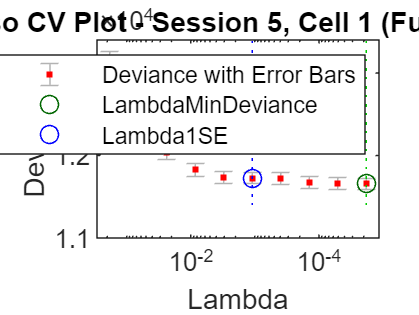

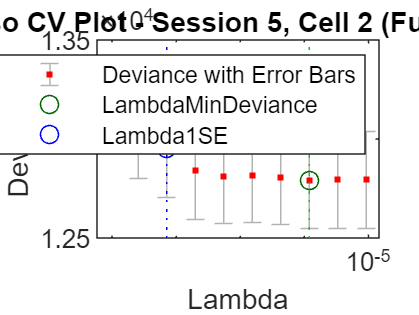

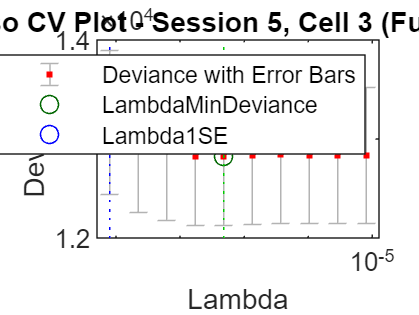


Finished Session 5.


Processing Session 6: Cell 

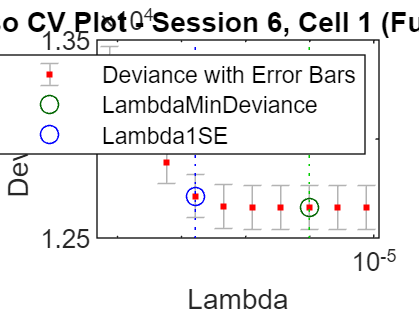

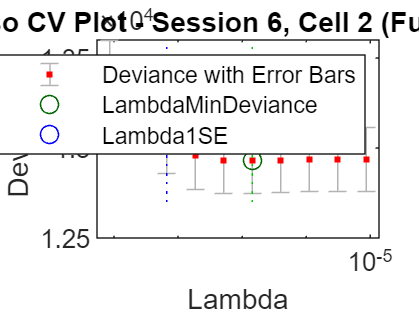

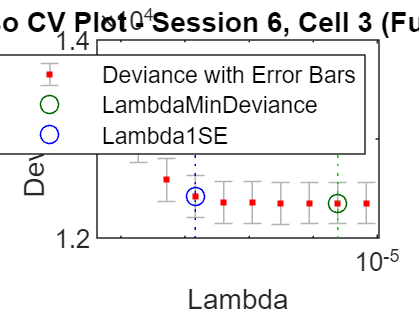


Finished Session 6.


Processing Session 7: Cell 

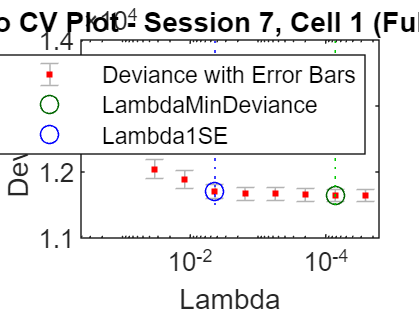

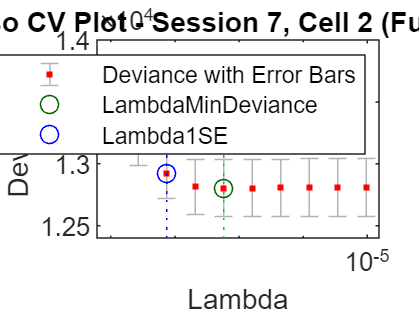

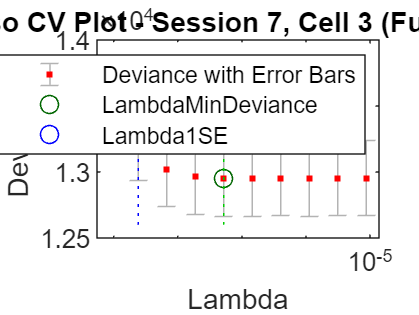


Finished Session 7.


Processing Session 8: Cell 

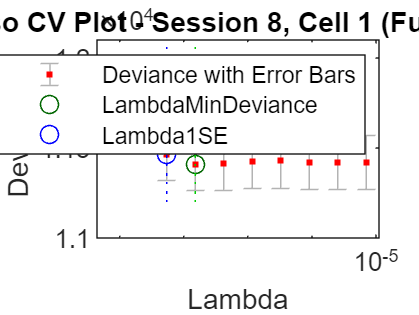

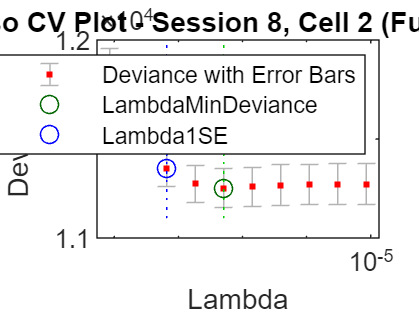

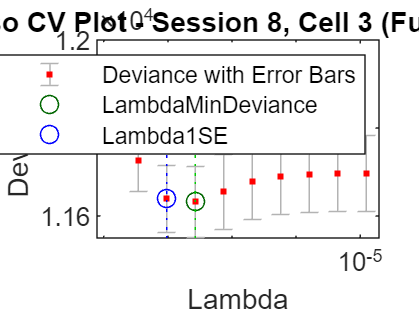


Finished Session 8.


Processing Session 9: Cell 

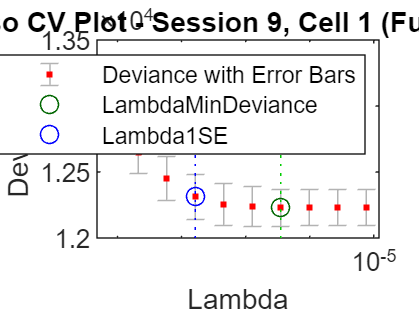

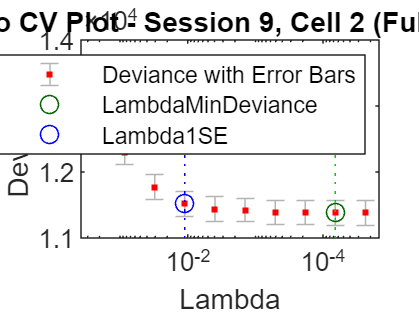

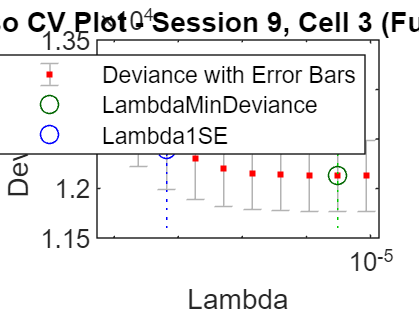


Finished Session 9.


Processing Session 10: Cell 

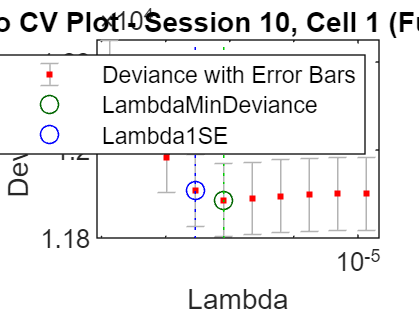

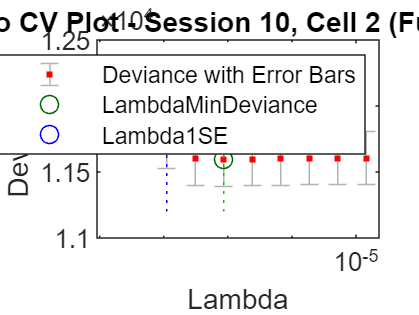

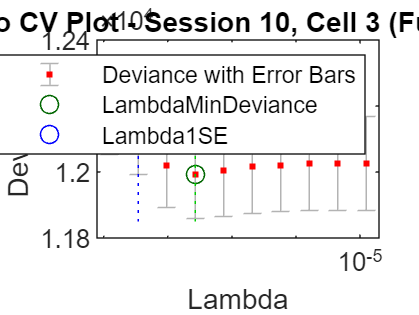


Finished Session 10.


Processing Session 11: Cell 

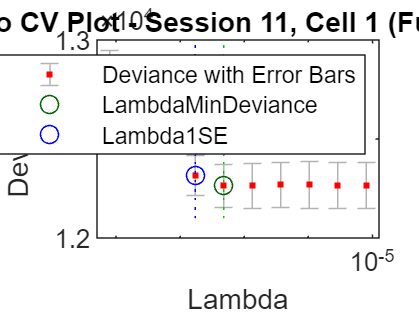

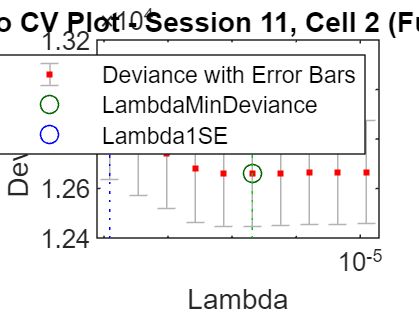

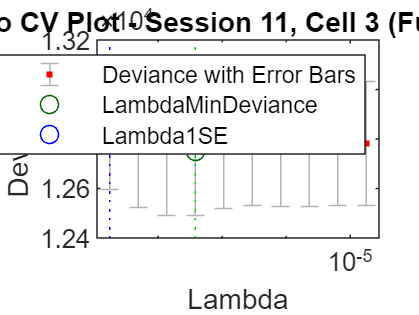


Finished Session 11.


Processing Session 12: Cell 

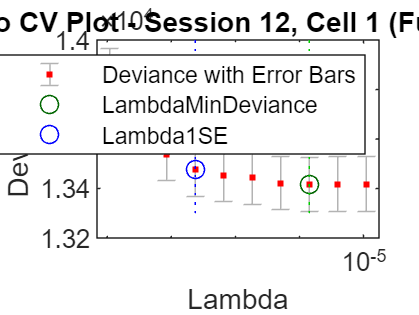

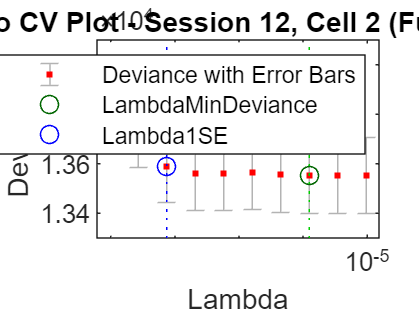

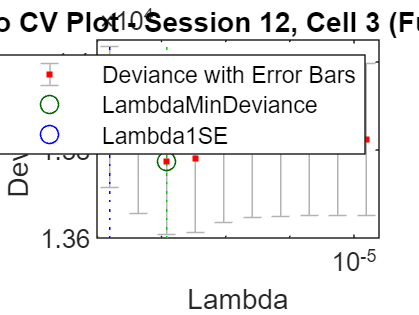


Finished Session 12.


Processing Session 13: Cell 

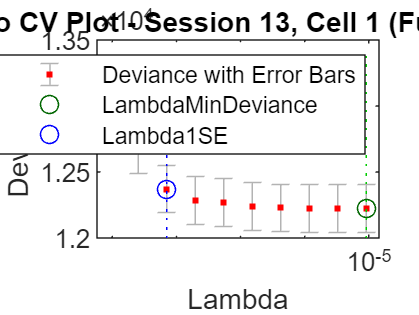

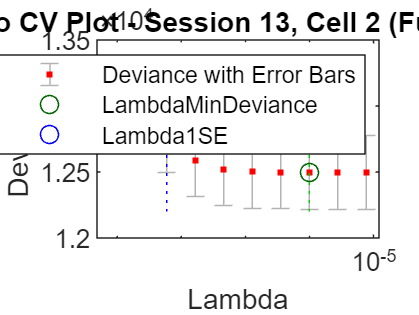

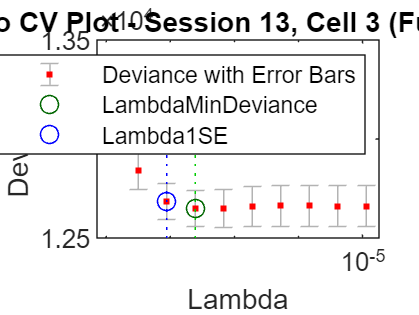


Finished Session 13.


%%%%%%%%%%%%%%%%%%%%% GLM encoding analysis %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
cv_num=5;
% --- Initialize result arrays ---
% Existing arrays for the full model
GLM = cell(1, length(Animal));
mincoefs = cell(1, length(Animal));
processed_neural_activity_data_pred = cell(1, length(Animal));

% ★ New arrays for the reduced models (only if bayes is true)
if bayes == true
    GLM_noPost = cell(1, length(Animal));
    mincoefs_noPost = cell(1, length(Animal));
    pred_noPost = cell(1, length(Animal)); % Renamed for clarity
    GLM_noNLL = cell(1, length(Animal));
    mincoefs_noNLL = cell(1, length(Animal));
    pred_noNLL = cell(1, length(Animal)); % Renamed for clarity
end

% --- Main Session Loop ---
for i_session = 1:length(Animal)
    
    % --- Initialize session-level result arrays ---
    num_cells_session = size(neural_activity_data{i_session}, 2);
    GLM_session = cell(num_cells_session, 2);
    mincoefs_session = cell(num_cells_session, 2);
    pred_session = cell(num_cells_session, 2); % Renamed
    
    % ★ Initialize session arrays for reduced models (only if bayes is true)
    if bayes == true
        GLM_noPost_session = cell(num_cells_session, 2);
        mincoefs_noPost_session = cell(num_cells_session, 2);
        pred_noPost_session = cell(num_cells_session, 2);
        GLM_noNLL_session = cell(num_cells_session, 2);
        mincoefs_noNLL_session = cell(num_cells_session, 2);
        pred_noNLL_session = cell(num_cells_session, 2);
        
        % ★ Define columns to exclude
        posterior_cols = 56:69; %57:70;
        nll_cols = 70:83; %71:84;
    end

    % --- Cell Loop ---
    fprintf('Processing Session %d: Cell ', i_session);
    for i_cell = 1:num_cells_session
        % fprintf('%d..', i_cell);

        % --- Determine input data based on 'test' flag ---
        if test == true
            X_data = behavior_data_train{i_session};
            Y_data = processed_neural_activity_data_train{i_session}(:, i_cell);
            X_data_test = behavior_data_test{i_session}; % For prediction later
        else
            X_data = behavior_data{i_session};
            Y_data = processed_neural_activity_data{i_session}(:, i_cell);
            X_data_test = behavior_data{i_session}; % For prediction later
        end

        % --- Determine distribution based on 'deconvolved' flag ---
        if deconvolved ~= true
            distribution = 'normal';
            link_function = 'identity';
        else
            distribution = 'poisson';
            link_function = 'log';
        end

        % --- 1. Fit FULL Model (Existing Code) ---
        try
            [B_full, FitInfo_full] = lassoglm(X_data, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_num, 'NumLambda', 10);
            GLM_session{i_cell, 1} = B_full;
            GLM_session{i_cell, 2} = FitInfo_full;

            % Extract coefficients for full model
            idxLambdaMinDeviance = FitInfo_full.IndexMinDeviance;
            B0 = FitInfo_full.Intercept(idxLambdaMinDeviance);
            mincoefs_session{i_cell, 1} = [B0; B_full(:, idxLambdaMinDeviance)];
            
            idxLambda1SE = FitInfo_full.Index1SE;
            B0_ = FitInfo_full.Intercept(idxLambda1SE);
            mincoefs_session{i_cell, 2} = [B0_; B_full(:, idxLambda1SE)];

            % Generate predictions for full model
            pred_session{i_cell, 1} = glmval(mincoefs_session{i_cell, 1}, X_data_test, link_function);
            pred_session{i_cell, 2} = glmval(mincoefs_session{i_cell, 2}, X_data_test, link_function);

        catch ME_full
            fprintf('\nError fitting full model for cell %d: %s\n', i_cell, ME_full.message);
        end
        
        % Plot for first few cells (optional)
        if i_cell <= 3 && exist('FitInfo_full', 'var')
            try % Wrap plot in try-catch in case FitInfo is empty
                figure; % Open a new figure for each plot
                lassoPlot(B_full, FitInfo_full, 'plottype', 'CV');
                legend('show');
                title(sprintf('Lasso CV Plot - Session %d, Cell %d (Full Model)', i_session, i_cell));
            catch ME_plot
                 fprintf('\nError plotting full model for cell %d: %s\n', i_cell, ME_plot.message);
            end
        end

        % --- 2. Fit REDUCED Models (Only if bayes is true) ---
        if bayes == true
            % --- a) Model excluding Posterior ---
            try
                cols_to_keep_noPost = setdiff(1:size(X_data, 2), posterior_cols);
                X_no_posterior = X_data(:, cols_to_keep_noPost);
                X_no_posterior_test = X_data_test(:, cols_to_keep_noPost);

                [B_noPost, FitInfo_noPost] = lassoglm(X_no_posterior, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_num, 'NumLambda', 10);
                GLM_noPost_session{i_cell, 1} = B_noPost;
                GLM_noPost_session{i_cell, 2} = FitInfo_noPost;

                % Extract coefficients
                idxMinDev = FitInfo_noPost.IndexMinDeviance;
                B0 = FitInfo_noPost.Intercept(idxMinDev);
                mincoefs_noPost_session{i_cell, 1} = [B0; B_noPost(:, idxMinDev)];
                
                idx1SE = FitInfo_noPost.Index1SE;
                B0_ = FitInfo_noPost.Intercept(idx1SE);
                mincoefs_noPost_session{i_cell, 2} = [B0_; B_noPost(:, idx1SE)];

                % Generate predictions
                pred_noPost_session{i_cell, 1} = glmval(mincoefs_noPost_session{i_cell, 1}, X_no_posterior_test, link_function);
                pred_noPost_session{i_cell, 2} = glmval(mincoefs_noPost_session{i_cell, 2}, X_no_posterior_test, link_function);
            catch ME_noPost
                fprintf('\nError fitting NoPosterior model for cell %d: %s\n', i_cell, ME_noPost.message);
            end

            % --- b) Model excluding Neg Log Likelihood ---
            try
                cols_to_keep_noNLL = setdiff(1:size(X_data, 2), nll_cols);
                X_no_nll = X_data(:, cols_to_keep_noNLL);
                X_no_nll_test = X_data_test(:, cols_to_keep_noNLL);

                [B_noNLL, FitInfo_noNLL] = lassoglm(X_no_nll, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_num, 'NumLambda', 10);
                GLM_noNLL_session{i_cell, 1} = B_noNLL;
                GLM_noNLL_session{i_cell, 2} = FitInfo_noNLL;

                % Extract coefficients
                idxMinDev = FitInfo_noNLL.IndexMinDeviance;
                B0 = FitInfo_noNLL.Intercept(idxMinDev);
                mincoefs_noNLL_session{i_cell, 1} = [B0; B_noNLL(:, idxMinDev)];

                idx1SE = FitInfo_noNLL.Index1SE;
                B0_ = FitInfo_noNLL.Intercept(idx1SE);
                mincoefs_noNLL_session{i_cell, 2} = [B0_; B_noNLL(:, idx1SE)];

                % Generate predictions
                pred_noNLL_session{i_cell, 1} = glmval(mincoefs_noNLL_session{i_cell, 1}, X_no_nll_test, link_function);
                pred_noNLL_session{i_cell, 2} = glmval(mincoefs_noNLL_session{i_cell, 2}, X_no_nll_test, link_function);
            catch ME_noNLL
                fprintf('\nError fitting NoNLL model for cell %d: %s\n', i_cell, ME_noNLL.message);
            end
        end % End of if bayes == true
        
        % Clear temporary variables for next cell
        clear B_* FitInfo_* X_* Y_* idx* B0* coefs_* 
    end % End of cell loop
    fprintf('\nFinished Session %d.\n', i_session);

    % --- Store session results in main arrays ---
    GLM{i_session} = GLM_session;
    mincoefs{i_session} = mincoefs_session;
    processed_neural_activity_data_pred{i_session} = pred_session; % Renamed

    if bayes == true
        GLM_noPost{i_session} = GLM_noPost_session;
        mincoefs_noPost{i_session} = mincoefs_noPost_session;
        pred_noPost{i_session} = pred_noPost_session; % Renamed
        GLM_noNLL{i_session} = GLM_noNLL_session;
        mincoefs_noNLL{i_session} = mincoefs_noNLL_session;
        pred_noNLL{i_session} = pred_noNLL_session; % Renamed
    end
    
    % Clear session variables before next session
    clear *_session X_data* Y_data* distribution link_function 

end % End of session loop


fprintf('\n--- GLM fitting complete. ---\n');


--- GLM fitting complete. ---


% %TODO: add code for posterior and prediction error GLM
% % palm
% GLM = cell(1,length(Animal));
% mincoefs = cell(1,length(Animal));
% processed_neural_activity_data_pred = cell(1,length(Animal));
% 
% for i_session = 1:length(Animal)
%     % num_cells_session = size(neural_activity_data{i_session}, 2);
%     GLM_session = cell(size(neural_activity_data{i_session},2),2);
%     mincoefs_session = cell(size(neural_activity_data{i_session},2),2);
%     processed_neural_activity_data_pred_session = cell(size(neural_activity_data{i_session},2),2);
% 
%     % for i_cell = 1:10 %10 for coding test
%     for i_cell = 1:size(neural_activity_data{i_session},2) %10 for coding test
%         if deconvolved ~= true
%             if test == true
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data_train{i_session},processed_neural_activity_data_train{i_session}(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%             else
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data{i_session},processed_neural_activity_data{i_session}(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%             end    
%         else
%             if test == true
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data_train{i_session},processed_neural_activity_data_train{i_session}(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
%             else
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data{i_session},processed_neural_activity_data{i_session}(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
%             end    
%         end
% 
%         if i_cell == 1 | i_cell == 2 | i_cell == 3
%             lassoPlot(GLM_session{i_cell,1},GLM_session{i_cell,2},'plottype','CV'); 
%             legend('show') % Show legend
%         end
%         idxLambdaMinDeviance = GLM_session{i_cell,2}.IndexMinDeviance;
%         % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
%         B0 = GLM_session{i_cell,2}.Intercept(idxLambdaMinDeviance);
%         mincoefs_session{i_cell,1} = [B0; GLM_session{i_cell,1}(:,idxLambdaMinDeviance)];
%         idxLambda1SE = GLM_session{i_cell,2}.Index1SE;
%         % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
%         B0_ = GLM_session{i_cell,2}.Intercept(idxLambda1SE);
%         mincoefs_session{i_cell,2} = [B0_; GLM_session{i_cell,1}(:,idxLambda1SE)];
%         % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
%         if deconvolved ~= true
%             if test == true
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data_test{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data_test{i_session},'identity'); 
%             else
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%             end
%         else
%             if test == true
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data_test{i_session},'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data_test{i_session},'log');  
%             else
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data{i_session},'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data{i_session},'log'); %,behavior_data_test,'log');
%             end
%         end       
%     end
%     GLM{i_session} = GLM_session;
%     mincoefs{i_session} = mincoefs_session;
%     processed_neural_activity_data_pred{i_session} = processed_neural_activity_data_pred_session;
% end

% % no CV to reduce computation time
% 
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),1);
% processed_neural_activity_data_pred = cell(size(neural_activity_data,2),1);
% for i_cell = 1:5
%     if deconvolved ~= true
% %     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'normal','Alpha',0.9,'CV',5,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'normal','Alpha',0.9,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%     else
% %         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'NumLambda',100);
%     end
% 
%     lassoPlot(GLM{i_cell,1},GLM{i_cell,2}); %,'plottype','CV'); 
%     legend('show') % Show legend
% %     idxLambdaMinDeviance = GLM{i_cell,2};
%     % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
%     B0 = GLM{i_cell,2}.Intercept;
%     mincoefs{i_cell} = [B0; GLM{i_cell,1}];
% %     idxLambda1SE = GLM{i_cell,2}.Index1SE;
% %     % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
% %     B0_ = GLM{i_cell,2}.Intercept(idxLambda1SE);
% %     mincoefs{i_cell,2} = [B0_; GLM{i_cell,1}(:,idxLambda1SE)];
%     % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
%     if deconvolved ~= true
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%     else
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'log'); %,behavior_data_test,'log');
%     end
% end

% % try ridge regression
% [GLM{i_cell,1}, GLM{i_cell,2}] = ridge(processed_neural_activity_data(:,i_cell),behavior_data,0.5)

% B0 = GLM{1,2}.Intercept(idxLambdaMinDeviance);
% coef = [B0; GLM{1,1}(:,idxLambdaMinDeviance)]
% processed_neural_activity_data_pred = glmval(coef,behavior_data_test,'log');
% 
% % calculate ^2
% SStot = sum((processed_neural_activity_data_test(:,1) - mean(processed_neural_activity_data_test(:,1))).^2);
% SSres = sum((processed_neural_activity_data_test(:,1) - processed_neural_activity_data_pred).^2);
% R2 = 1 - SSres/SStot;
% fprintf('Explained Variation (R^2) = %.2f\n', R2);

addpath([working_directory  filesep 'Utility' filesep 'Subaxis']);

% % plot actual and predicted neural activity
% example_num = 5; % 5;
% figure
% for i_cell = 1:example_num
% %     SStot = sum((processed_neural_activity_data_test(:,i_cell) - mean(processed_neural_activity_data_test(:,i_cell))).^2);
%     SStot = sum((processed_neural_activity_data(:,i_cell) - mean(processed_neural_activity_data(:,i_cell))).^2);
%     SSres = sum((processed_neural_activity_data(:,i_cell) - processed_neural_activity_data_pred{i_cell}).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
% %     plot(1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_test(:,i_cell),1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,1},1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,2});
%     plot(1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data(:,i_cell),1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data_pred{i_cell});
%     title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
%     
%     ylabel('normalized neural activity');
% %     ylim([-0.2 1.2]);
% %     xlim([0 max(p_time_temp_transformed)]);
% end
% xlabel('time');
%     legend({'Actual','Predicted'},'Location','northeast');
% 
% % figure
% % for i = 1:example_num
% %     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
% %     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% % %     title([brain_roi_name(i)], 'FontSize',6);
% %     ylim(ylimit); 
% %     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% % %     ylabel('neural activity');
% % %     xlabel('time (sec)')
% % end

% plot actual and predicted neural activity
example_num =  5;
figure
for i_cell = 1:example_num
    if test == true
        SStot = sum((processed_neural_activity_data_test{1}(:,i_cell) - mean(processed_neural_activity_data_test{1}(:,i_cell))).^2);        
        SSres = sum((processed_neural_activity_data_test{1}(:,i_cell) - processed_neural_activity_data_pred{1}{i_cell,1}).^2);
    else
        SStot = sum((processed_neural_activity_data{1}(:,i_cell) - mean(processed_neural_activity_data{1}(:,i_cell))).^2);
        SSres = sum((processed_neural_activity_data{1}(:,i_cell) - processed_neural_activity_data_pred{1}{i_cell,1}).^2);
    end    
    R2 = 1 - SSres/SStot
    subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
    % plot(1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_test{1}(:,i_cell),1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,1},1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,2});
    plot(1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data{1}(:,i_cell),1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,1},1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,2});
    title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
    ylabel('normalized neural activity');
%     ylim([-0.2 1.2]);
%     xlim([0 max(p_time_temp_transformed)]);
end

R2 = 0.0133

R2 = 0.0407

R2 = 0.0461

R2 = 0.0636

R2 = 0.0724

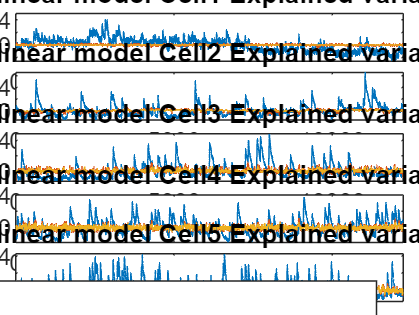

xlabel('time');
legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northeast');
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_GLM_raw_activity_prediction.png'];
saveas(gcf,filename);     


% figure
% for i = 1:example_num
%     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% %     ylabel('neural activity');
% %     xlabel('time (sec)')
% end

%% --- 全細胞のモデル性能を評価 ---

% testフラグに応じて使用するデータセットを選択
if test == true
    actual_data = processed_neural_activity_data_test{1};
    predicted_data = processed_neural_activity_data_pred{1}; % MinDevianceモデルを使用
else
    actual_data = processed_neural_activity_data{1};
    predicted_data = processed_neural_activity_data_pred{1};
end

num_cells = size(actual_data, 2); % 全細胞数を取得

% 各評価指標を保存するための配列を初期化
correlations = NaN(num_cells, 1);
explained_variances = NaN(num_cells, 1);
r2_values = NaN(num_cells, 1);

% 全ての細胞についてループ
for i_cell = 1:num_cells
    % 実際の活動データと、モデルによる予測データを取得
    y_actual = actual_data(:, i_cell);
    y_pred = predicted_data{i_cell, 1}; % {i_cell, 1}はMinDevianceモデルの予測値

    % データにNaNやInfが含まれている場合は計算をスキップ
    if any(isnan(y_actual)) || any(isinf(y_actual)) || any(isnan(y_pred)) || any(isinf(y_pred))
        continue;
    end
    
    % 1. 相関係数 (Pearson's r)
    correlations(i_cell) = corr(y_actual, y_pred);
    
    % 2. R2乗値 (決定係数)
    SStot = sum((y_actual - mean(y_actual)).^2);
    SSres = sum((y_actual - y_pred).^2);
    r2_values(i_cell) = 1 - SSres / SStot;
    
    % 3. Explained Variance
    residuals = y_actual - y_pred;
    explained_variances(i_cell) = 1 - var(residuals) / var(y_actual);
end

% Count the total number of cells with valid (non-NaN) R^2 values
    valid_r2_count = sum(~isnan(r2_values));
    
    if valid_r2_count > 0
        % Count cells with R^2 >= 0.02
        count_above_02 = sum(r2_values >= 0.02, 'omitnan');
        % Calculate percentage
        percent_above_02 = (count_above_02 / valid_r2_count) * 100;
        
        % Count cells with R^2 >= 0.1
        count_above_10 = sum(r2_values >= 0.1, 'omitnan');
        % Calculate percentage
        percent_above_10 = (count_above_10 / valid_r2_count) * 100;
        
        % Print the results
        fprintf('\n--- Model Performance Summary ---\n');
        fprintf('Total cells with valid R^2: %d\n', valid_r2_count);
        fprintf('Percentage of cells with R^2 >= 0.02: %.2f%%\n', percent_above_02);
        fprintf('Percentage of cells with R^2 >= 0.10: %.2f%%\n', percent_above_10);
    else
        fprintf('\n--- Model Performance Summary ---\n');
        fprintf('No valid R^2 values found to calculate percentages.\n');
    end


--- Model Performance Summary ---


Total cells with valid R^2: 104


Percentage of cells with R^2 >= 0.02: 96.15%


Percentage of cells with R^2 >= 0.10: 6.73%


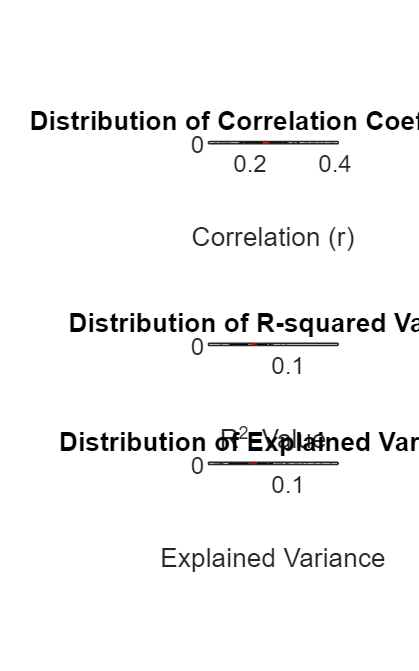


%% --- 評価指標のヒストグラムをプロット ---

figure('Position', [100, 100, 500, 800]);
tiledlayout(3, 1, 'TileSpacing', 'compact'); % 3x1のレイアウト

% --- 1. 相関係数のヒストグラム ---
nexttile;
histogram(correlations, 50);
hold on;
mean_corr = mean(correlations, 'omitnan');
xline(mean_corr, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_corr));
title('Distribution of Correlation Coefficients');
xlabel('Correlation (r)');
ylabel('Number of Cells');
grid on;

% --- 2. R2乗値のヒストグラム ---
nexttile;
histogram(r2_values, 50);
hold on;
mean_r2 = mean(r2_values, 'omitnan');
xline(mean_r2, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_r2));
title('Distribution of R-squared Values');
xlabel('R^2 Value');
ylabel('Number of Cells');
grid on;

% --- 3. Explained Varianceのヒストグラム ---
nexttile;
histogram(explained_variances, 50);
hold on;
mean_ev = mean(explained_variances, 'omitnan');
xline(mean_ev, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_ev));
title('Distribution of Explained Variance');
xlabel('Explained Variance');
ylabel('Number of Cells');
grid on;

% ファイルに保存
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_GLM_performance_histograms.png'];
saveas(gcf, filename);

% TODO: have to reconstruct force act because there is overlap between
% consequensive force act
% force_idx_ori
i_session = 1

i_session = 1

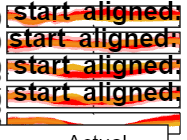


% if strcmp(clip, 'Trial')
    %% --- 準備：クリップ済みインデックスと使用するデータの選択 ---
    
    % 保存したクリップ済みインデックスを読み込む
    event_indices_clipped = clip_idxs_behavior{i_session};
    
    % testフラグに応じて、使用するデータセットを選択
    if test == true
        neural_data_to_plot = processed_neural_activity_data_test{i_session};
        pred_data_to_plot = processed_neural_activity_data_pred{i_session}; % test用の予測データも必要
    else
        neural_data_to_plot = processed_neural_activity_data{i_session};
        pred_data_to_plot = processed_neural_activity_data_pred{i_session};
    end    
    %% --- Trial Start 周辺の活動をプロット ---
    
    ts_indices = event_indices_clipped.trial_start; % Trial Startのクリップ済みインデックス
    
    figure;
    for i_cell = 1:example_num
        % イベントごとの活動を格納する行列を初期化
        trial_start_act      = NaN(length(ts_indices), fps * (after_event) + 1);
        trial_start_act_pred = NaN(length(ts_indices), fps * (after_event) + 1);
        
        for j = 1:length(ts_indices)
            event_time = ts_indices(j);
            start_window = event_time;
            end_window   = event_time + fps * after_event;

            % ウィンドウがデータの範囲内に収まっているかチェック
            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                trial_start_act(j, :)      = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                trial_start_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end    
        % NaNを無視して平均とSEMを計算
        trial_start_act_mean = mean(trial_start_act, 1, 'omitnan');
        trial_start_act_pred_mean = mean(trial_start_act_pred, 1, 'omitnan');
        trial_start_act_SEM = std(trial_start_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(trial_start_act(:,1))));
        trial_start_act_SEM_pred = std(trial_start_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(trial_start_act_pred(:,1))));

        % R2の計算
        SStot = sum((trial_start_act_mean - mean(trial_start_act_mean)).^2);
        SSres = sum((trial_start_act_mean - trial_start_act_pred_mean).^2);
        R2 = 1 - SSres / SStot;

        % プロット
        subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = 0:1/fps:after_event; % X軸を秒単位に
        x2 = [x, fliplr(x)];
        hold on;
        plot(x, trial_start_act_mean, 'r', 'LineWidth', 2);
        plot(x, trial_start_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
        % SEMの描画
        fill(x2, [trial_start_act_mean + trial_start_act_SEM, fliplr(trial_start_act_mean - trial_start_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        fill(x2, [trial_start_act_pred_mean + trial_start_act_SEM_pred, fliplr(trial_start_act_pred_mean - trial_start_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        xline(0, '--k');
        title(['Cell' num2str(i_cell) ' Trial start aligned: R^2 = ' num2str(R2, '%.2f')]);
        hold off;
        if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
    end
    xlabel('Time from trial start (s)');
    legend({'Actual', 'Predicted'}, 'Location', 'northeast');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_trial_start_ETA_prediction.png'];
    saveas(gcf, filename);

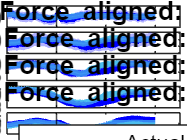


    %% --- Pull Force 周辺の活動をプロット ---
    
    pull_indices = event_indices_clipped.pull_force;
    
    figure;
    for i_cell = 1:example_num
        Pull_act      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        Pull_act_pred = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        
        for j = 1:length(pull_indices)
            event_time = pull_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Pull_act(j, :)      = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Pull_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end

        % NaNを無視して平均とSEMを計算
        Pull_act_mean = mean(Pull_act, 1, 'omitnan');
        Pull_act_pred_mean = mean(Pull_act_pred, 1, 'omitnan');
        Pull_act_SEM = std(Pull_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act(:,1))));
        Pull_act_SEM_pred = std(Pull_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act_pred(:,1))));
        
        SStot = sum((Pull_act_mean - mean(Pull_act_mean, 'omitnan')).^2);
        SSres = sum((Pull_act_mean - Pull_act_pred_mean).^2);
        R2 = 1 - SSres / SStot;

        % プロット
        subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:1/fps:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x, Pull_act_mean, 'b', 'LineWidth', 2); % Pullは青色に
        plot(x, Pull_act_pred_mean, 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2); % 予測は水色に
        fill(x2, [Pull_act_mean + Pull_act_SEM, fliplr(Pull_act_mean - Pull_act_SEM)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        fill(x2, [Pull_act_pred_mean + Pull_act_SEM_pred, fliplr(Pull_act_pred_mean - Pull_act_SEM_pred)], [0.3010 0.7450 0.9330], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        xline(0, '--k');
        title(['Cell' num2str(i_cell) ' Pull Force aligned: R^2 = ' num2str(R2, '%.2f')]);
        hold off;
        if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
    end
    xlabel('Time from pull onset (s)');
    legend({'Actual', 'Predicted'}, 'Location', 'northwest');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_pull_force_ETA_prediction.png'];
    saveas(gcf, filename);

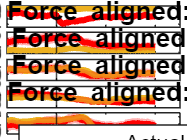


    %% --- Push Force 周辺の活動をプロット ---
    
    push_indices = event_indices_clipped.push_force;
    
    figure;
    for i_cell = 1:example_num
        Push_act      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        Push_act_pred = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        
        for j = 1:length(push_indices)
            event_time = push_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Push_act(j, :)      = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Push_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end

        % NaNを無視して平均とSEMを計算
        Push_act_mean = mean(Push_act, 1, 'omitnan');
        Push_act_pred_mean = mean(Push_act_pred, 1, 'omitnan');
        Push_act_SEM = std(Push_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act(:,1))));
        Push_act_SEM_pred = std(Push_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act_pred(:,1))));
        
        SStot = sum((Push_act_mean - mean(Push_act_mean, 'omitnan')).^2);
        SSres = sum((Push_act_mean - Push_act_pred_mean).^2);
        R2 = 1 - SSres / SStot;

        % プロット
        subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
        x = -before_event:1/fps:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x, Push_act_mean, 'r', 'LineWidth', 2); % Pushは赤色に
        plot(x, Push_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2); % 予測はオレンジに
        fill(x2, [Push_act_mean + Push_act_SEM, fliplr(Push_act_mean - Push_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        fill(x2, [Push_act_pred_mean + Push_act_SEM_pred, fliplr(Push_act_pred_mean - Push_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        xline(0, '--k');
        title(['Cell' num2str(i_cell) ' Push Force aligned: R^2 = ' num2str(R2, '%.2f')]);
        hold off;
        if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
    end
    xlabel('Time from push onset (s)');
    legend({'Actual', 'Predicted'}, 'Location', 'northwest');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_push_force_ETA_prediction.png'];
    saveas(gcf, filename);

% end

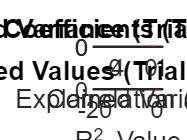

% if strcmp(clip, 'Trial')

    %% --- 1. Trial Start イベントでの性能評価 ---
    
    ts_indices = event_indices_clipped.trial_start;
    
    % 各評価指標を全細胞分保存するための配列を初期化
    ts_correlations = NaN(num_cells, 1);
    ts_r2_values = NaN(num_cells, 1);
    ts_explained_variances = NaN(num_cells, 1);
    
    % 全ての細胞についてループ
    for i_cell = 1:num_cells
        % イベントごとの活動を格納
        trial_start_act      = NaN(length(ts_indices), fps * after_event + 1);
        trial_start_act_pred = NaN(length(ts_indices), fps * after_event + 1);
        
        for j = 1:length(ts_indices)
            event_time = ts_indices(j);
            start_window = event_time;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                trial_start_act(j, :)      = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                trial_start_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        
        % 平均イベント周り活動を計算
        act_mean = mean(trial_start_act, 1, 'omitnan');
        pred_mean = mean(trial_start_act_pred, 1, 'omitnan');

        % データがない場合はスキップ
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end

        % 3つの評価指標を計算
        ts_correlations(i_cell) = corr(act_mean', pred_mean');
        ts_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        ts_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end
    
    % ヒストグラムをプロット
    figure('Name', 'Performance Histograms: Trial Start Aligned');
    create_performance_histograms(ts_correlations, ts_r2_values, ts_explained_variances, 'Trial Start');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_trial_start.png'];
    saveas(gcf, filename);

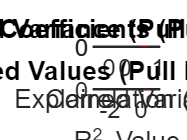


    %% --- 2. Pull Force イベントでの性能評価 ---
    
    pull_indices = event_indices_clipped.pull_force;
    
    pull_correlations = NaN(num_cells, 1);
    pull_r2_values = NaN(num_cells, 1);
    pull_explained_variances = NaN(num_cells, 1);

    for i_cell = 1:num_cells
        Pull_act      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        Pull_act_pred = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        for j = 1:length(pull_indices)
            event_time = pull_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;
            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Pull_act(j, :) = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Pull_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        act_mean = mean(Pull_act, 1, 'omitnan');
        pred_mean = mean(Pull_act_pred, 1, 'omitnan');
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end
        
        pull_correlations(i_cell) = corr(act_mean', pred_mean');
        pull_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        pull_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end

    figure('Name', 'Performance Histograms: Pull Force Aligned');
    create_performance_histograms(pull_correlations, pull_r2_values, pull_explained_variances, 'Pull Force');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_pull_force.png'];
    saveas(gcf, filename);

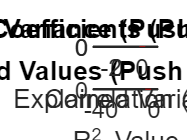


    %% --- 3. Push Force イベントでの性能評価 ---
    
    push_indices = event_indices_clipped.push_force;

    push_correlations = NaN(num_cells, 1);
    push_r2_values = NaN(num_cells, 1);
    push_explained_variances = NaN(num_cells, 1);

    for i_cell = 1:num_cells
        Push_act      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        Push_act_pred = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        for j = 1:length(push_indices)
            event_time = push_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;
            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Push_act(j, :) = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Push_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        act_mean = mean(Push_act, 1, 'omitnan');
        pred_mean = mean(Push_act_pred, 1, 'omitnan');
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end
        
        push_correlations(i_cell) = corr(act_mean', pred_mean');
        push_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        push_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end

    figure('Name', 'Performance Histograms: Push Force Aligned');
    create_performance_histograms(push_correlations, push_r2_values, push_explained_variances, 'Push Force');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_push_force.png'];
    saveas(gcf, filename);

% end

% % before_event = 2; %1;
% % after_event  = 4; %2;
% force        = behavior_neural_time(:,7);
% force_idx    = find(force > force_thr);
% cur_RecICA{block} = zeros(example_num,(before_event+after_event)*fps/1000+1);
% if timepoints(block,1)<1
%     before_start = - timepoints(block,1);
%     cur_RecICA{block}(:,1:before_start+1) = NaN;
%     cur_RecICA{block}(:,before_start+2:(before+after)*fps/1000+1) = RecICA_Temp{block}(:,1:timepoints(block,2));
% elseif timepoints(block,2)>size(RecICA_Temp{block},2)
%     after_end = timepoints(block,2) - size(RecICA_Temp{block},2);
%     cur_RecICA{block}(:,(before+after)*fps/1000+1-after_end:(before+after)*fps/1000+1) = NaN;
%     cur_RecICA{block}(:,1:(before+after)*fps/1000-after_end) = RecICA_Temp{block}(:,timepoints(block,1):size(RecICA_Temp{block},2));
% else
%     cur_RecICA{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
% end

% [GLM{1,1}, GLM{1,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,1),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend
% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))
% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend

% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))

% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

% --- Pre-calculate R^2 for ALL cells ---
all_r2_values = cell(1, length(Animal)); % Store R^2 for each session

fprintf('Calculating R^2 values for all cells...\n');

Calculating R^2 values for all cells...


for i_session = 1:length(Animal)
    % Select data based on test flag
    if test == true
        actual_data_session = processed_neural_activity_data_test{i_session};
        predicted_data_session = processed_neural_activity_data_pred{i_session}; %_test{i_session}; % Assuming _test exists
    else
        actual_data_session = processed_neural_activity_data{i_session};
        predicted_data_session = processed_neural_activity_data_pred{i_session};
    end
    
    num_cells_session = size(actual_data_session, 2);
    r2_session = NaN(num_cells_session, 1); % Initialize R^2 for this session

    for i_cell = 1:num_cells_session
        y_actual = actual_data_session(:, i_cell);
        % Use Lambda1SE coefficients for R^2 calculation (index {i_cell, 2})
        % Make sure predicted_data_session format matches {cell, model_type}
        y_pred = predicted_data_session{i_cell, 2}; % Using Lambda1SE prediction

        % Skip if data has NaN/Inf
        if any(isnan(y_actual)) || any(isinf(y_actual)) || any(isnan(y_pred)) || any(isinf(y_pred))
            continue;
        end

        % Calculate R^2
        SStot = sum((y_actual - mean(y_actual)).^2);
        SSres = sum((y_actual - y_pred).^2);
        
        % Avoid division by zero if SStot is very small or zero
        if SStot > eps % Use machine epsilon as tolerance
             r2_session(i_cell) = 1 - SSres / SStot;
        else
             r2_session(i_cell) = NaN; % Assign NaN if total variance is zero
        end
    end
    all_r2_values{i_session} = r2_session; % Store R^2 vector for the session
end
fprintf('R^2 calculation complete.\n');

R^2 calculation complete.


 % trial_start_conv, trial_end_conv, resistance_high_conv,
 % resistance_low_conv, position_conv, force_conv, reward_conv,
 % licking_conv
 % 1-7,8-14,15-21,22-28,29-34,35-41,42-48,49-55
 % old:1-5,6-10,11-15,16-20,21-26,27-31,32-38
 % use Lambda1SE
cell_representations = cell(1,length(Animal));

for i_session = 1:length(Animal)
    neural_activity_data_session = neural_activity_data{i_session};
    mincoefs_session = mincoefs{i_session};

     trial_start_cell_session = zeros(size(neural_activity_data_session,2),1);
     trial_end_cell_session = zeros(size(neural_activity_data_session,2),1);
     pullResistance_cell_session = zeros(size(neural_activity_data_session,2),1);     
     pushResistance_cell_session = zeros(size(neural_activity_data_session,2),1);
     position_cell_session = zeros(size(neural_activity_data_session,2),1);
     force_cell_session = zeros(size(neural_activity_data_session,2),1);
     reward_cell_session = zeros(size(neural_activity_data_session,2),1);
     licking_cell_session = zeros(size(neural_activity_data_session,2),1);
     state_value_cell_session = zeros(size(neural_activity_data_session,2),1);
     action_value_cell_session = zeros(size(neural_activity_data_session,2),1);
     % pullResistance_cell_session = zeros(size(neural_activity_data_session,2),1);
     % pushResistance_cell_session = zeros(size(neural_activity_data_session,2),1);     
     % pull_obs_cell_session = zeros(size(neural_activity_data_session,2),1);
     % push_obs_cell_session = zeros(size(neural_activity_data_session,2),1);  
     % pull_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);
     % push_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);     
     pull_posterior_cell_session = zeros(size(neural_activity_data_session,2),1);
     push_posterior_cell_session = zeros(size(neural_activity_data_session,2),1);
     pull_neg_log_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);     
     push_neg_log_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);  
    
     for i_cell = 1:size(neural_activity_data_session,2)
        if sum(mincoefs_session{i_cell,2}(2:8)) > 0
            trial_start_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(9:15)) > 0
            trial_end_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(16:22)) > 0
            pullResistance_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(23:29)) > 0
            pushResistance_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(30:35)) > 0
            position_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(36:42)) > 0
            force_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(43:49)) > 0
            reward_cell_session(i_cell) = 1;
        end
        if sum(mincoefs_session{i_cell,2}(50:56)) > 0
            licking_cell_session(i_cell) = 1;
        end
        if bayes == true
            if sum(mincoefs_session{i_cell,2}(57:63)) > 0
                pull_posterior_cell_session(i_cell) = 1;
            end
            if sum(mincoefs_session{i_cell,2}(54:70)) > 0
                push_posterior_cell_session(i_cell) = 1;
            end            
            if sum(mincoefs_session{i_cell,2}(71:77)) > 0
                pull_neg_log_likelihood_cell_session(i_cell) = 1;
            end        
            if sum(mincoefs_session{i_cell,2}(78:84)) > 0
                push_neg_log_likelihood_cell_session(i_cell) = 1;
            end               
        elseif state_action_value == true
            if sum(mincoefs_session{i_cell,2}(57:66)) > 0
                state_value_cell_session(i_cell) = 1;
            end
            if sum(mincoefs_session{i_cell,2}(67:96)) > 0
                action_value_cell_session(i_cell) = 1;
            end
        end
     end
    if bayes == true
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, pullResistance_cell_session, pushResistance_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, pull_posterior_cell_session, push_posterior_cell_session, pull_neg_log_likelihood_cell_session, push_neg_log_likelihood_cell_session];        
    elseif state_action_value == true
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];
    else
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session];
    end
    % cell_representations{i_session} = cell_representations_session;
    
    % --- Filter based on R^2 threshold ---
    r2_values_session = all_r2_values{i_session};
    % Create mask: R^2 >= threshold AND R^2 is not NaN
    r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session); 
    
    cell_representations{i_session} = cell_representations_session(r2_mask, :);
    
    fprintf('Session %d: %d cells total, %d cells passed R^2 >= %.2f threshold.\n', ...
            i_session, length(r2_mask), sum(r2_mask), R_thres);    
end

Session 1: 104 cells total, 6 cells passed R^2 >= 0.10 threshold.
Session 2: 296 cells total, 36 cells passed R^2 >= 0.10 threshold.
Session 3: 297 cells total, 64 cells passed R^2 >= 0.10 threshold.
Session 4: 287 cells total, 51 cells passed R^2 >= 0.10 threshold.
Session 5: 65 cells total, 5 cells passed R^2 >= 0.10 threshold.
Session 6: 41 cells total, 9 cells passed R^2 >= 0.10 threshold.
Session 7: 26 cells total, 4 cells passed R^2 >= 0.10 threshold.
Session 8: 9 cells total, 1 cells passed R^2 >= 0.10 threshold.
Session 9: 38 cells total, 3 cells passed R^2 >= 0.10 threshold.
Session 10: 65 cells total, 6 cells passed R^2 >= 0.10 threshold.
Session 11: 366 cells total, 39 cells passed R^2 >= 0.10 threshold.
Session 12: 440 cells total, 21 cells passed R^2 >= 0.10 threshold.
Session 13: 475 cells total, 55 cells passed R^2 >= 0.10 threshold.


cell_representations_conc = cell_representations{1};
for i_animal = 2:length(Animal)
    cell_representations_conc = vertcat(cell_representations_conc, cell_representations{i_animal});
end

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));

for i = 1:length(Animal)        
    if image_reverse{i} == 0
        depth{i} = 1050 - neural_property_data{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    elseif image_reverse{i} == 1
        depth{i} = 1050 - neural_property_data{i}(:,4)*1050/(1280/4); 
    else
        depth{i} = neural_property_data{i}(:,4)*1050/(1280/4);
%     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    end
end
depth_conc = depth{1};
for i_animal = 2:length(Animal)
    depth_conc = vertcat(depth_conc, depth{i_animal});
end

% % neural_traits_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces-props.csv']);%,'NumHeaderLines',1);
% neural_traits_table = readtable([data_folder filesep 'cell_traces-props.csv']); %Linux
% % centroidY = neural_traits_table.('CentroidY')
% centroidX = neural_traits_table.('CentroidX') % corresponding cortical depth
% if image_reverse == 0;
%     depth = 1100 - centroidX*900/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% else
%     depth = centroidX*900/(1280/4);
% %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% end

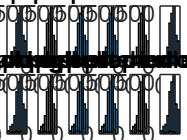

% plot the relation between position and representaion of each variables
if state_action_value == true
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'posterior cell', 'pred error cell', 'state val. cell', 'action val. cell'};
    for i = 1:10
        subaxis(2,5,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.04);
        edges = [0:100:900];
        h1 = histogram(depth_conc,edges); %centroidY);
        hold on
        h2 = histogram(depth_conc(cell_representations_conc(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
else
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'pull res. cell', 'push res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'pull posterior cell', 'push posterior cell', 'pull pred error cell', 'push pred error cell'};
    for i = 1:12
        subaxis(2,6,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.02);
        edges = [0:100:900];
        h1 = histogram(depth_conc,edges); %centroidY);
        hold on
        h2 = histogram(depth_conc(cell_representations_conc(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
end
filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_distribution.png'];
saveas(gcf,filename);

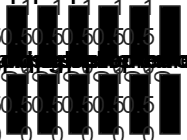

% plot ratio
if state_action_value == true %| bayes == true
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'high res. cell', 'low res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'posterior cell', 'pred error cell', 'state val. cell', 'action val. cell'};
    for i = 1:10
        subaxis(2,5,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.04);
        edges = [0:100:1100];
        h1 = histcounts(depth_conc,edges); %centroidY);
        h2 = histcounts(depth_conc(cell_representations_conc(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        h_ratio = h2 ./ h1;
        bar(edges(1:end-1), h1 ./ h1,'FaceColor','cyan');
        hold on
        bar(edges(1:end-1), h_ratio,'FaceColor','magenta');
        ylim([0 1]);        
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
else
    figure
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start cell', 'trial end cell', 'pull res. cell', 'push res. cell', 'position cell', 'force cell', 'reward cell', 'licking cell', 'pull posterior cell', 'push posterior cell', 'pull pred error cell', 'push pred error cell'};
    for i = 1:12
        subaxis(2,6,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.02);
        edges = [0:100:900];
        h1 = histcounts(depth_conc,edges); %centroidY);
        h2 = histcounts(depth_conc(cell_representations_conc(:,i)==1),edges); %centroidY(cell_representations(:,i)==1));
        h_ratio = h2 ./ h1;
        bar(edges(1:end-1), h1 ./ h1); %,'FaceColor','cyan');
        xticks([0 1000]);
        hold on
        bar(edges(1:end-1), h_ratio); %,'FaceColor','magenta');
        ylim([0 1]);
        title(titles(i), 'FontSize',8);
%         xlabel('cell depth');
%         ylabel('cell number');
    end
end
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio.png'];
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio.png'];
saveas(gcf,filename);

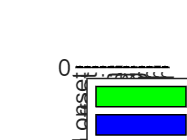

if layer == true 
    if state_action_value == true %| bayes == true
        layer_cell_representations = zeros(10,2); %cell(1,length(Animal));
        for i = 1:10
            sum_cell_representations_layer23 = 0;
            sum_cell_representations_layer5 = 0;
            sum_layer23 = 0;
            sum_layer5 = 0;
            for i_session = 1:length(Animal) 
                % layer_cell_representations_session = zeros(10,2);
                pointAreas_session = pointAreas_data{i_session};
                cell_representations_session = cell_representations{i_session};
                sum_cell_representations_layer23 = sum_cell_representations_layer23 + sum(cell_representations_session(:,i)&pointAreas_session);
                sum_cell_representations_layer5 = sum_cell_representations_layer5 + sum(cell_representations_session(:,i)&(~pointAreas_session)); 
                sum_layer23 = sum_layer23 + sum(pointAreas_session);
                sum_layer5 = sum_layer5 + sum(~pointAreas_session);            
    
                % layer_cell_representations_session(i,:) = [sum(cell_representations_session(:,i)&pointAreas_session)/sum(pointAreas_session),sum(cell_representations_session(:,i)&(~pointAreas_session))/sum(~pointAreas_session)];
            end
            layer_cell_representations(i,:) = [sum_cell_representations_layer23/sum_layer23, sum_cell_representations_layer5/sum_layer5];
            % layer_cell_representations{i_session} = layer_cell_representations_session;
        end
        % layer_cell_representations_conc = layer_cell_representations{1};
        % for i_animal = 2:length(Animal)
        %     layer_cell_representations_conc = vertcat(layer_cell_representations_conc, layer_cell_representations{i_animal});
        % end
        conditions = 1:10;
        figure;
        hold on;
        bar(conditions - 0.2, layer_cell_representations(:,1), 'g','BarWidth',0.4);
        bar(conditions + 0.2, layer_cell_representations(:,2), 'b','BarWidth',0.4);
        
        legend('layer 2/3', 'layer 5', 'Location', 'northwest');
        
        ylabel('Behavior cells');
        xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
        xticks(conditions);
        xticklabels(xlabels);
        xlim([0.5, 10.5]);    
        xtickangle(90);
    else
        layer_cell_representations = zeros(12,2); %cell(1,length(Animal));
        for i = 1:12
            sum_cell_representations_layer23 = 0;
            sum_cell_representations_layer5 = 0;
            sum_filtered_layer23 = 0;
            sum_filtered_layer5 = 0;
            for i_session = 1:length(Animal) 
                % layer_cell_representations_session = zeros(10,2);
                % pointAreas_session = pointAreas_data{i_session};
                % 1. Get the R^2 mask for the current session
                r2_values_session = all_r2_values{i_session};
                r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
                
                % 2. Get the already filtered cell representations for this session
                cell_representations_session_filtered = cell_representations{i_session};
                
                % 3. Filter the pointAreas data using the SAME R^2 mask
                pointAreas_session_unfiltered = pointAreas_data{i_session};
                pointAreas_session_filtered = pointAreas_session_unfiltered(r2_mask); 

                cell_representations_session = cell_representations{i_session};
                sum_cell_representations_layer23 = sum_cell_representations_layer23 + sum(cell_representations_session_filtered(:,i)&pointAreas_session_filtered);
                sum_cell_representations_layer5 = sum_cell_representations_layer5 + sum(cell_representations_session_filtered(:,i)&(~pointAreas_session_filtered)); 
                sum_filtered_layer23 = sum_filtered_layer23 + sum(pointAreas_session_filtered);
                sum_filtered_layer5 = sum_filtered_layer5 + sum(~pointAreas_session_filtered);            
    
                % layer_cell_representations_session(i,:) = [sum(cell_representations_session(:,i)&pointAreas_session)/sum(pointAreas_session),sum(cell_representations_session(:,i)&(~pointAreas_session))/sum(~pointAreas_session)];
            end
            % Calculate the final ratio, handle division by zero
            if sum_filtered_layer23 > 0
                ratio_l23 = sum_cell_representations_layer23 / sum_filtered_layer23;
            else
                ratio_l23 = NaN; % Assign NaN if no filtered L2/3 cells
            end
            
            if sum_filtered_layer5 > 0
                ratio_l5 = sum_cell_representations_layer5 / sum_filtered_layer5;
            else
                ratio_l5 = NaN; % Assign NaN if no filtered L5 cells
            end            
            layer_cell_representations(i,:) = [ratio_l23, ratio_l5];            
            % layer_cell_representations(i,:) = [sum_cell_representations_layer23/sum_layer23, sum_cell_representations_layer5/sum_layer5];
            % layer_cell_representations{i_session} = layer_cell_representations_session;
        end
        % layer_cell_representations_conc = layer_cell_representations{1};
        % for i_animal = 2:length(Animal)
        %     layer_cell_representations_conc = vertcat(layer_cell_representations_conc, layer_cell_representations{i_animal});
        % end   
        conditions = 1:12;
        figure;
        hold on;
        bar(conditions - 0.2, layer_cell_representations(:,1), 'g','BarWidth',0.4);
        bar(conditions + 0.2, layer_cell_representations(:,2), 'b','BarWidth',0.4);
        
        legend('layer 2/3', 'layer 5', 'Location', 'northwest');
        
        ylabel('Behavior cells');
        xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred. error', 'push pred. error'};
        xticks(conditions);
        xticklabels(xlabels);
        xlim([0.5, 12.5]);    
        xtickangle(90);
    end
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_layer_compare.png'];
    saveas(gcf,filename);
end

% GLM_230210 = GLM;

% save table as mat file
save([data_parent_dir filesep 'GLM_'  strrep(strjoin(uniqueAnimal),' ','_')  '.mat'], 'GLM');
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM'); % 'GLM_230210');
% save([data_parent_dir filesep strrep(strjoin(uniqueDate),' ','_') '_GLM_'  strrep(strjoin(uniqueAnimal),' ','_')  '.mat'], 'GLM');

% plot pie graph
        % cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];

if state_action_value == true
    data = cell(1,length(Animal));
    state_state_value_cells = cell(1,length(Animal));
    action_action_value_cells = cell(1,length(Animal));
    ssv_aav_cells = cell(1,length(Animal));
    for i_session = 1:length(Animal)   
        resistance_high_cell = cell_representations{i_session}(:,3);
        resistance_low_cell = cell_representations{i_session}(:,4);
        position_cell = cell_representations{i_session}(:,5);
        force_cell = cell_representations{i_session}(:,6);
        state_value_cell = cell_representations{i_session}(:,9);
        action_value_cell = cell_representations{i_session}(:,10);
        state_state_value_cell = (resistance_high_cell|resistance_low_cell|position_cell)&state_value_cell;
        action_action_value_cell = force_cell&action_value_cell;
        ssv_aav_cell = state_state_value_cell & action_action_value_cell;
        neither_num = length(ssv_aav_cell)+nnz(ssv_aav_cell)-nnz(state_state_value_cell)-nnz(action_action_value_cell);
        data{i_session} = [nnz(ssv_aav_cell),nnz(state_state_value_cell),nnz(action_action_value_cell),neither_num];
        state_state_value_cells{i_session} = state_state_value_cell;
        action_action_value_cells{i_session} = action_action_value_cell;
        ssv_aav_cells{i_session} = ssv_aav_cell;
    end
    data_conc = data{1};
    for i_animal = 2:length(Animal)
        data_conc = data_conc + data{i_animal};  % 各要素の位置ごとに足し合わせる
    end   
    labels = {['state and action value'],['state value'],['action value'], ['neither']};

    figure
    p = pie(data_conc); %,labels); 
    title({['Ratio of value neurons (n=' num2str(sum(data_conc)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data_conc(1)) ')']; ['(' num2str(data_conc(2)) ')']; ['(' num2str(data_conc(3)) ')']; ['(' num2str(data_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_state_action_value_cells_pie.png'];
    saveas(gcf,filename);
end

%% TODO: support of sig_cell && layer
if layer == true & state_action_value == true
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    data23 = cell(1,length(Animal));
    data5 = cell(1,length(Animal));
    for i_session = 1:length(Animal)  
        pointAreas_data_session = pointAreas_data{i_session};
        state_state_value_cell = state_state_value_cells{i_session};
        action_action_value_cell = action_action_value_cells{i_session};
        ssv_aav_cell = ssv_aav_cells{i_session};
        state_state_value_cells_session = {state_state_value_cell(find(pointAreas_data_session == 1)), state_state_value_cell(find(pointAreas_data_session == 0))};
        action_action_value_cells_session = {action_action_value_cell(find(pointAreas_data_session == 1)), action_action_value_cell(find(pointAreas_data_session == 0))};
        ssv_aav_cells_session = {ssv_aav_cell(find(pointAreas_data_session == 1)), ssv_aav_cell(find(pointAreas_data_session == 0))};
        neither_num23 = sum(pointAreas_data_session)+nnz(ssv_aav_cells_session{1})-nnz(state_state_value_cells_session{1})-nnz(action_action_value_cells_session{1});
        neither_num5  = length(pointAreas_data_session)-sum(pointAreas_data_session)+nnz(ssv_aav_cells_session{2})-nnz(state_state_value_cells_session{2})-nnz(action_action_value_cells_session{2}); 
    
        data23{i_session} = [nnz(ssv_aav_cells_session{1}),nnz(state_state_value_cells_session{1}),nnz(action_action_value_cells_session{1}),neither_num23];
        data5{i_session} = [nnz(ssv_aav_cells_session{2}),nnz(state_state_value_cells_session{2}),nnz(action_action_value_cells_session{2}),neither_num5];
    end  
    data23_conc = data23{1};
    data5_conc = data5{1};    
    for i_animal = 2:length(Animal)
        data23_conc = data23_conc + data23{i_animal};
        data5_conc = data5_conc + data5{i_animal};        
    end        
    labels = {['state and action value'],['state value'],['action value'],['neither']};
    figure
    p = pie(data23_conc); %, labels); 
%     title({['Layer2/3: Ratio of value neurons (n=' num2str(sum(data23)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data23_conc(1)) ')']; ['(' num2str(data23_conc(2)) ')']; ['(' num2str(data23_conc(3)) ')']; ['(' num2str(data23_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_state_action_value_cells_pie.png'];
    saveas(gcf,filename);    

    labels = {['state and action value'],['state value'],['action value'], ['neither']};
    figure
    p = pie(data5_conc); %, labels); %depth,'filled');
%     title({['Layer5: Ratio of value neurons (n=' num2str(sum(data5)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data5_conc(1)) ')']; ['(' num2str(data5_conc(2)) ')']; ['(' num2str(data5_conc(3)) ')']; ['(' num2str(data5_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_state_action_value_cells_pie.png'];
    saveas(gcf,filename);     
end

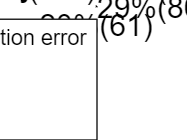

% plot pie graph
        % cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];
if bayes == true
    data = cell(1,length(Animal));
    posterior_cells = cell(1,length(Animal));
    prediction_error_cells = cell(1,length(Animal));
    pos_err_cells = cell(1,length(Animal));
    for i_session = 1:length(Animal)   
        posterior_cell = cell_representations{i_session}(:,9) | cell_representations{i_session}(:,10);
        prediction_error_cell = cell_representations{i_session}(:,11) | cell_representations{i_session}(:,12);    
        pos_err_cell = posterior_cell & prediction_error_cell;
        total_cells = length(posterior_cell); % このセッションの総細胞数
        both_num = nnz(pos_err_cell); % 「両方」の細胞数
        posterior_only_num = nnz(posterior_cell) - both_num;
        prediction_error_only_num = nnz(prediction_error_cell) - both_num;
        neither_num = total_cells - (both_num + posterior_only_num + prediction_error_only_num);
        data{i_session} = [both_num, posterior_only_num, prediction_error_only_num, neither_num];
        posterior_cells{i_session} = posterior_cell;
        prediction_error_cells{i_session} = prediction_error_cell;
        pos_err_cells{i_session} = pos_err_cell;
    end
    data_conc = data{1};
    for i_animal = 2:length(Animal)
        data_conc = data_conc + data{i_animal};  % 各要素の位置ごとに足し合わせる
    end   
    labels = {['posterior and prediction error'],['posterior'],['prediction error'], ['neither']};
    
    figure
    p = pie(data_conc); %,labels); 
    title({['Ratio of Bayesian neurons (n=' num2str(sum(data_conc)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data_conc(1)) ')']; ['(' num2str(data_conc(2)) ')']; ['(' num2str(data_conc(3)) ')']; ['(' num2str(data_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);
end

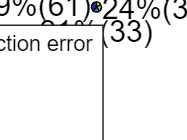

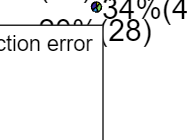

%% TODO: support of sig_cell && layer
if layer == true & bayes == true
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    data23 = cell(1,length(Animal));
    data5 = cell(1,length(Animal));
    for i_session = 1:length(Animal)  
        % pointAreas_data_session = pointAreas_data{i_session};
        % posterior_cell = posterior_cells{i_session};
        % prediction_error_cell = prediction_error_cells{i_session};
        % pos_err_cell = pos_err_cells{i_session};
        % 1. Get the R^2 mask for the current session
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        
        % 2. Filter pointAreas and cell classification data using the R^2 mask
        pointAreas_session_filtered = pointAreas_data{i_session}(r2_mask);
        posterior_cell_filtered = posterior_cells{i_session};
        prediction_error_cell_filtered = prediction_error_cells{i_session};
        pos_err_cell_filtered = pos_err_cells{i_session};        

        % --- 脳領域ごとに細胞を分割 ---
        is_area23 = (pointAreas_session_filtered == 1);
        is_area5 = (pointAreas_session_filtered == 0);
        
        posterior_cells_23 = posterior_cell_filtered(is_area23);
        prediction_error_cells_23 = prediction_error_cell_filtered(is_area23);
        pos_err_cells_23 = pos_err_cell_filtered(is_area23);
    
        posterior_cells_5 = posterior_cell_filtered(is_area5);
        prediction_error_cells_5 = prediction_error_cell_filtered(is_area5);
        pos_err_cells_5 = pos_err_cell_filtered(is_area5);
    
        % === Area 2/3 の集計 ===
        total_cells_23 = length(posterior_cells_23);
        both_num_23 = nnz(pos_err_cells_23);
        posterior_only_num_23 = nnz(posterior_cells_23) - both_num_23;
        prediction_error_only_num_23 = nnz(prediction_error_cells_23) - both_num_23;
        neither_num_23 = total_cells_23 - (both_num_23 + posterior_only_num_23 + prediction_error_only_num_23);
        
        data23{i_session} = [both_num_23, posterior_only_num_23, prediction_error_only_num_23, neither_num_23];
    
        % === Area 5 の集計 ===
        total_cells_5 = length(posterior_cells_5);
        both_num_5 = nnz(pos_err_cells_5);
        posterior_only_num_5 = nnz(posterior_cells_5) - both_num_5;
        prediction_error_only_num_5 = nnz(prediction_error_cells_5) - both_num_5;
        neither_num_5 = total_cells_5 - (both_num_5 + posterior_only_num_5 + prediction_error_only_num_5);
    
        data5{i_session} = [both_num_5, posterior_only_num_5, prediction_error_only_num_5, neither_num_5];
    end  
    data23_conc = data23{1};
    data5_conc = data5{1};    
    for i_animal = 2:length(Animal)
        data23_conc = data23_conc + data23{i_animal};
        data5_conc = data5_conc + data5{i_animal};        
    end        
    labels = {['posterior and prediction error'],['posterior'],['prediction error'],['neither']};
    figure
    p = pie(data23_conc); %, labels); 
%     title({['Layer2/3: Ratio of value neurons (n=' num2str(sum(data23)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data23_conc(1)) ')']; ['(' num2str(data23_conc(2)) ')']; ['(' num2str(data23_conc(3)) ')']; ['(' num2str(data23_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_layer23_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);    

    labels = {['posterior and prediction error'],['posterior'],['prediction error'], ['neither']};
    figure
    p = pie(data5_conc); %, labels); %depth,'filled');
%     title({['Layer5: Ratio of value neurons (n=' num2str(sum(data5)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data5_conc(1)) ')']; ['(' num2str(data5_conc(2)) ')']; ['(' num2str(data5_conc(3)) ')']; ['(' num2str(data5_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_layer5_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);     
end

if layer == true && bayes == true
    
    % --- Initialize storage for proportions per session ---
    proportions23 = cell(1, length(Animal));
    proportions5 = cell(1, length(Animal));
    
    fprintf('Calculating layer-specific cell type proportions (filtered by R^2 >= %.2f)...\n', R_thres);
    
    % --- Loop through sessions to calculate proportions ---
    for i_session = 1:length(Animal)
        
        % 1. Get R^2 mask
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        
        % 2. Filter relevant data
        pointAreas_session_filtered = pointAreas_data{i_session}(r2_mask);
        posterior_cell_filtered = posterior_cells{i_session};
        prediction_error_cell_filtered = prediction_error_cells{i_session};
        pos_err_cell_filtered = pos_err_cells{i_session};
        
        % --- Split filtered cells by layer ---
        is_area23_filtered = (pointAreas_session_filtered == 1);
        is_area5_filtered = (pointAreas_session_filtered == 0);
        
        % --- Calculate proportions for Layer 2/3 ---
        total_cells_23_filtered = sum(is_area23_filtered);
        if total_cells_23_filtered > 0
            posterior_cells_23 = posterior_cell_filtered(is_area23_filtered);
            prediction_error_cells_23 = prediction_error_cell_filtered(is_area23_filtered);
            pos_err_cells_23 = pos_err_cell_filtered(is_area23_filtered);
            
            both_num_23 = nnz(pos_err_cells_23);
            posterior_only_num_23 = nnz(posterior_cells_23) - both_num_23;
            prediction_error_only_num_23 = nnz(prediction_error_cells_23) - both_num_23;
            neither_num_23 = total_cells_23_filtered - (both_num_23 + posterior_only_num_23 + prediction_error_only_num_23);
            
            % Store proportions (counts / total filtered cells in this layer for this session)
            proportions23{i_session} = [both_num_23, posterior_only_num_23, prediction_error_only_num_23, neither_num_23] / total_cells_23_filtered;
        else
            proportions23{i_session} = [NaN, NaN, NaN, NaN]; % Use NaN if no cells
        end
        
        % --- Calculate proportions for Layer 5 ---
        total_cells_5_filtered = sum(is_area5_filtered);
        if total_cells_5_filtered > 0
            posterior_cells_5 = posterior_cell_filtered(is_area5_filtered);
            prediction_error_cells_5 = prediction_error_cell_filtered(is_area5_filtered);
            pos_err_cells_5 = pos_err_cell_filtered(is_area5_filtered);
            
            both_num_5 = nnz(pos_err_cells_5);
            posterior_only_num_5 = nnz(posterior_cells_5) - both_num_5;
            prediction_error_only_num_5 = nnz(prediction_error_cells_5) - both_num_5;
            neither_num_5 = total_cells_5_filtered - (both_num_5 + posterior_only_num_5 + prediction_error_only_num_5);
            
            proportions5{i_session} = [both_num_5, posterior_only_num_5, prediction_error_only_num_5, neither_num_5] / total_cells_5_filtered;
        else
            proportions5{i_session} = [NaN, NaN, NaN, NaN]; % Use NaN if no cells
        end
    end
    
    % --- Aggregate proportions into matrices (Session x Category) ---
    proportions_matrix_23 = cat(1, proportions23{:});
    proportions_matrix_5 = cat(1, proportions5{:});
    
    % --- Calculate Mean and SEM across sessions ---
    mean_prop_23 = mean(proportions_matrix_23, 1, 'omitnan');
    sem_prop_23 = std(proportions_matrix_23, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_23(:,1)))); % SEM based on valid sessions
    
    mean_prop_5 = mean(proportions_matrix_5, 1, 'omitnan');
    sem_prop_5 = std(proportions_matrix_5, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_5(:,1))));
    
    % --- Perform Wilcoxon Rank-Sum Test for each category ---
    labels = {'Both', 'Posterior Only', 'PE Only', 'Neither'}; % Shortened labels
    p_values_ranksum = NaN(1, length(labels));
    
    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Proportions) ---\n');
    for i_cat = 1:length(labels)
        data1 = proportions_matrix_23(:, i_cat);
        data2 = proportions_matrix_5(:, i_cat);
        
        % Remove NaN pairs before testing
        valid_idx = ~isnan(data1) & ~isnan(data2);
        if sum(valid_idx) > 1 % Need at least 2 valid pairs
            p_values_ranksum(i_cat) = ranksum(data1(valid_idx), data2(valid_idx));
            fprintf('%s: p = %.4f\n', labels{i_cat}, p_values_ranksum(i_cat));
        else
            fprintf('%s: Not enough data for test\n', labels{i_cat});
        end
    end
    
    % --- Plotting ---
    figure('Position', [100, 100, 450, 350], 'Color', 'w'); % Adjusted size
    hold on;
    
    num_categories = length(labels);
    group_means = [mean_prop_23', mean_prop_5']; % Transpose means for bar function
    group_sems = [sem_prop_23', sem_prop_5'];
    
    b = bar(1:num_categories, group_means, 'grouped');
    
    % Add error bars
    num_groups = size(group_means, 1); % Should be 4 (categories)
    num_bars = size(group_means, 2);   % Should be 2 (layers)
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    x_centers = (1:num_groups)'; % Center x-coordinates for each category group
    
    for i = 1:num_bars
        % Calculate center of bars for this layer within each group
        bar_centers = x_centers - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(bar_centers, group_means(:, i), group_sems(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;
    
    % --- Style and Labels ---
    b(1).FaceColor = [0 .6 0]; % L2/3 Color (Green)
    b(2).FaceColor = [0 0.3 0.9]; % L5 Color (Blue)
    
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    ylabel('Mean Proportion of Cells', 'FontSize', 10);
    xticks(1:num_categories);
    xticklabels(labels);
    xtickangle(45);
    xlim([0.5, num_categories + 0.5]);
    ylim([0, max(group_means(:) + group_sems(:)) * 1.1 + 0.01]); % Adjust Y limit + small margin
    
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('Layer Comparison (Cells with R^2 >= %.2f)', R_thres), 'FontSize', 10);
    grid on;

    % --- Save ---
    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_bayes_cell_proportions_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename, '-dsvg');
    close(gcf);
    
end

Calculating layer-specific cell type proportions (filtered by R^2 >= 0.10)...



--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Proportions) ---


Both: p = 0.4100
Posterior Only: p = 0.9473
PE Only: p = 0.0651
Neither: p = 0.7255


% --- Compare R^2 drop for reduced models in well-explained cells ---

if bayes == true % Only run if reduced models were fitted

    fprintf('\nCalculating SESSION-AVERAGED R^2 drop (using cells with Full Model R^2 >= %.2f)...\n', R_thres);

    % --- Initialize storage for SESSION-AVERAGED R^2 drops ---
    session_mean_drop_noPost_L23 = NaN(length(Animal), 1);
    session_mean_drop_noPost_L5  = NaN(length(Animal), 1);
    session_mean_drop_noNLL_L23  = NaN(length(Animal), 1);
    session_mean_drop_noNLL_L5   = NaN(length(Animal), 1);

    % --- Loop through sessions ---
    for i_session = 1:length(Animal)

        % --- Get data for the current session ---
        r2_full_session = all_r2_values{i_session};
        pointAreas_session = pointAreas_data{i_session};

        % Select actual data based on test flag
        if test == true
            actual_data_session = processed_neural_activity_data_test{i_session};
            pred_full_session_cell = processed_neural_activity_data_pred_test{i_session};
            pred_noPost_session = pred_noPost_test{i_session};
            pred_noNLL_session = pred_noNLL_test{i_session};
        else
            actual_data_session = processed_neural_activity_data{i_session};
            pred_full_session_cell = processed_neural_activity_data_pred{i_session};
            pred_noPost_session = pred_noPost{i_session};
            pred_noNLL_session = pred_noNLL{i_session};
        end

        num_cells_session = size(actual_data_session, 2);

        % --- Identify well-explained cells based on FULL model R^2 ---
        r2_mask = (r2_full_session >= R_thres) & ~isnan(r2_full_session);
        filtered_cell_indices = find(r2_mask);

        if isempty(filtered_cell_indices)
            fprintf('Session %d: No cells passed R^2 threshold. Skipping.\n', i_session);
            continue; % Skip session if no cells pass threshold
        end

        pointAreas_filtered = pointAreas_session(filtered_cell_indices);

        % --- Calculate R^2 for reduced models ONLY for filtered cells ---
        r2_noPost_filtered = NaN(length(filtered_cell_indices), 1);
        r2_noNLL_filtered  = NaN(length(filtered_cell_indices), 1);
        r2_full_filtered   = r2_full_session(filtered_cell_indices);

        for k = 1:length(filtered_cell_indices)
            i_cell = filtered_cell_indices(k);
            y_actual = actual_data_session(:, i_cell);
            y_pred_noPost = pred_noPost_session{i_cell, 2};
            y_pred_noNLL  = pred_noNLL_session{i_cell, 2};

            if any(isnan(y_actual)) || any(isinf(y_actual)) || ...
               any(isnan(y_pred_noPost)) || any(isinf(y_pred_noPost)) || ...
               any(isnan(y_pred_noNLL)) || any(isinf(y_pred_noNLL))
                continue;
            end

            SStot = sum((y_actual - mean(y_actual)).^2);
            if SStot > eps
                SSres_noPost = sum((y_actual - y_pred_noPost).^2);
                SSres_noNLL  = sum((y_actual - y_pred_noNLL).^2);
                r2_noPost_filtered(k) = 1 - SSres_noPost / SStot;
                r2_noNLL_filtered(k)  = 1 - SSres_noNLL  / SStot;
            end
        end

        % --- Calculate R^2 Drop for this session's filtered cells ---
        drop_noPost = r2_full_filtered - r2_noPost_filtered;
        drop_noNLL  = r2_full_filtered - r2_noNLL_filtered;

        % --- Separate drops by layer ---
        is_l23_filtered = (pointAreas_filtered == 1);
        is_l5_filtered  = (pointAreas_filtered == 0);

        % --- Calculate MEAN R^2 drop PER LAYER within THIS SESSION ---
        session_mean_drop_noPost_L23(i_session) = mean(drop_noPost(is_l23_filtered), 'omitnan');
        session_mean_drop_noPost_L5(i_session)  = mean(drop_noPost(is_l5_filtered), 'omitnan');
        session_mean_drop_noNLL_L23(i_session)  = mean(drop_noNLL(is_l23_filtered), 'omitnan');
        session_mean_drop_noNLL_L5(i_session)   = mean(drop_noNLL(is_l5_filtered), 'omitnan');

    end % End session loop

    % --- Calculate Mean and SEM across SESSION AVERAGES ---
    mean_across_sessions_noPost_L23 = mean(session_mean_drop_noPost_L23, 'omitnan');
    sem_across_sessions_noPost_L23  = std(session_mean_drop_noPost_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noPost_L23)));
    mean_across_sessions_noPost_L5  = mean(session_mean_drop_noPost_L5, 'omitnan');
    sem_across_sessions_noPost_L5   = std(session_mean_drop_noPost_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noPost_L5)));

    mean_across_sessions_noNLL_L23  = mean(session_mean_drop_noNLL_L23, 'omitnan');
    sem_across_sessions_noNLL_L23   = std(session_mean_drop_noNLL_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noNLL_L23)));
    mean_across_sessions_noNLL_L5   = mean(session_mean_drop_noNLL_L5, 'omitnan');
    sem_across_sessions_noNLL_L5    = std(session_mean_drop_noNLL_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noNLL_L5)));

    % --- Perform Wilcoxon Rank-Sum Test (L2/3 vs L5 for each model) ---
    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Session Averages) ---\n');
    
    % Test for 'Removed Posterior' model
    data1_noPost = session_mean_drop_noPost_L23;
    data2_noPost = session_mean_drop_noPost_L5;
    valid_idx_noPost = ~isnan(data1_noPost) & ~isnan(data2_noPost); % Use only valid session pairs
    if sum(valid_idx_noPost) > 1
        p_noPost = ranksum(data1_noPost(valid_idx_noPost), data2_noPost(valid_idx_noPost));
        fprintf('Removed Posterior: L2/3 vs L5, p = %.4f\n', p_noPost);
    else
        p_noPost = NaN;
        fprintf('Removed Posterior: Not enough valid session pairs for test.\n');
    end

    % Test for 'Removed NegLogLikelihood' model
    data1_noNLL = session_mean_drop_noNLL_L23;
    data2_noNLL = session_mean_drop_noNLL_L5;
    valid_idx_noNLL = ~isnan(data1_noNLL) & ~isnan(data2_noNLL); % Use only valid session pairs
    if sum(valid_idx_noNLL) > 1
        p_noNLL = ranksum(data1_noNLL(valid_idx_noNLL), data2_noNLL(valid_idx_noNLL));
        fprintf('Removed NegLogLikelihood: L2/3 vs L5, p = %.4f\n', p_noNLL);
    else
        p_noNLL = NaN;
        fprintf('Removed NegLogLikelihood: Not enough valid session pairs for test.\n');
    end
    
    % Store p-values if needed, e.g., in a structure
    test_results.p_noPost = p_noPost;
    test_results.p_noNLL = p_noNLL;

    % --- Create Bar Plot (Using Session Averages) ---
    figure('Position', [100, 100, 400, 350], 'Color', 'w');

    means_session_avg = [mean_across_sessions_noPost_L23, mean_across_sessions_noPost_L5; ...
                         mean_across_sessions_noNLL_L23,  mean_across_sessions_noNLL_L5];
    sems_session_avg  = [sem_across_sessions_noPost_L23,  sem_across_sessions_noPost_L5;  ...
                         sem_across_sessions_noNLL_L23,   sem_across_sessions_noNLL_L5];

    b = bar(means_session_avg, 'grouped');
    hold on;

    num_groups = size(means_session_avg, 1);
    num_bars = size(means_session_avg, 2);
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    for i = 1:num_bars
        x = (1:num_groups) - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(x, means_session_avg(:, i), sems_session_avg(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;

    % --- Style and Labels ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;

    b(1).FaceColor = [0 .6 0]; % L2/3 Color
    b(2).FaceColor = [0 0.3 0.9]; % L5 Color

    ylabel('Mean Session \DeltaR^2 (Full - Reduced)', 'FontSize', 10); % Updated label
    xticklabels({'Removed Posterior', 'Removed NegLogLikelihood'});
    legend({'L2/3', 'L5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('R^2 Drop (Session Avg, Full R^2 >= %.2f)', R_thres), 'FontSize', 10); % Updated title
    ylim([0, max(means_session_avg(:) + sems_session_avg(:)) * 1.1 + 0.001]); % Add small margin
    grid on;

    % --- Save ---
    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_R2_drop_SessionAvg_comparison_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename, '-dsvg');
    close(gcf);

else
    fprintf('\nBayes flag is not true. Skipping R^2 drop comparison.\n');
end % End of if bayes == true


Calculating SESSION-AVERAGED R^2 drop (using cells with Full Model R^2 >= 0.10)...



--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Session Averages) ---


Removed Posterior: L2/3 vs L5, p = 0.4701


Removed NegLogLikelihood: L2/3 vs L5, p = 0.4701


% z test to see difference of ratio (ligh reward activated vs low reward activated)
% [h, p, ci, stats] = proptest(sum(ssv_aav_cells{1}),length(ssv_aav_cells{1}),sum(ssv_aav_cells{2}),length(ssv_aav_cells{2}),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);
% print(['state:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

% kari_x = [1 1 0 0 0 0 0 0 0 0];
% kari_y = [1 1 1 1 1 0 0 0 0 0];
% [h, p, ci, stats] = ztest(kari_x,sum(kari_x),kari_y,sum(kari_y),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

% % plot example neural activity
% neither_cell = ~(state_state_value_cell | action_action_value_cell | ssv_aav_cell);
% categories = {state_state_value_cell, action_action_value_cell, ssv_aav_cell, neither_cell};
% category_str = {['state_and_action_value'],['state_value'],['action_value'], ['neither_value']};
% force_idx_idx   = find_indices(force_idx_ori,force_idx);
% 
% resistance       = behavior_neural_time(:,5);
% resistance(nan_time,:)  = [];
% force_state_high_idx    = [];
% force_state_low_idx     = [];
% res_all  = unique(sort(resistance));
% res_high = res_all(2);
% res_low  = res_all(1);
% for i = 1:length(force_idx_idx)
%     if strcmp(clip, 'Force')
%         resistance = resisance(force_idx,:)
%         if force_idx_idx(i)+fps < length(resistance)
%             temp_resistance = min(resistance(force_idx_idx(i):force_idx_idx(i)+fps)); % expand 1 sec to include force just before trial
%         else
%             temp_resistance = resistance(force_idx_idx(i));
%         end
%         if temp_resistance == Inf
%             continue; % skip for loop
%         elseif temp_resistance == res_high
%             force_state_high_idx(end+1) = force_idx_idx(i);
%         elseif temp_resistance == res_low
%             force_state_low_idx(end+1)  = force_idx_idx(i);
%         end
%     else
%         if force_idx(force_idx_idx(j))+fps < length(resistance)
%             temp_resistance = min(resistance(force_idx(force_idx_idx(i)):force_idx(force_idx_idx(i))+fps)); % expand 1 sec to include force just before trial
%         else
%             temp_resistance = resistance(force_idx(force_idx_idx(i)));
%         end
%         if temp_resistance == Inf
%             continue; % skip for loop
%         elseif temp_resistance == res_high
%             force_state_high_idx(end+1) = force_idx_idx(i);
%         elseif temp_resistance == res_low
%             force_state_low_idx(end+1)  = force_idx_idx(i);
%         end        
%     end
% end

% example_num = 5;
% 
% for m = 1:length(categories)
%     figure
%     m_category = categories{m};
%     all_cell = find(m_category == 1);
%     for i = 1:example_num
%         i_cell = all_cell(i);
%         Force_act       = zeros(length(force_idx_idx),fps*(before_event+after_event)+1);
%         Force_act_high  = zeros(length(force_state_high_idx),fps*(before_event+after_event)+1);     
%         Force_act_low   = zeros(length(force_state_low_idx),fps*(before_event+after_event)+1);  
%         for j = 1:length(force_idx_idx)
%             if strcmp(clip, 'Force')
%                 Force_act(j,:) = transpose(processed_neural_activity_data(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event,i_cell));
%             else
%                 Force_act(j,:) = transpose(processed_neural_activity_data(force_idx(force_idx_idx(j))-fps*before_event:force_idx(force_idx_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         for j = 1:length(force_state_high_idx)
%             if strcmp(clip, 'Force')
%                 Force_act_high(j,:) = transpose(processed_neural_activity_data(force_state_high_idx(j)-fps*before_event:force_state_high_idx(j)+fps*after_event,i_cell));   
%             else                
%                 Force_act_high(j,:) = transpose(processed_neural_activity_data(force_idx(force_state_high_idx(j))-fps*before_event:force_idx(force_state_high_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         for j = 1:length(force_state_low_idx)        
%             if strcmp(clip, 'Force')
%                 Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_state_low_idx(j)-fps*before_event:force_state_low_idx(j)+fps*after_event,i_cell));
%             else
%                 Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_idx(force_state_low_idx(j))-fps*before_event:force_idx(force_state_low_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         Force_act_SEM = std(Force_act,0,1)/sqrt(size(Force_act,1));
%         Force_act_high_SEM = std(Force_act_high,0,1)/sqrt(size(Force_act_high,1));
%         Force_act_low_SEM  = std(Force_act_low,0,1)/sqrt(size(Force_act_low,1));        
%         Force_act = mean(Force_act,1);
%         Force_act_high = mean(Force_act_high,1);
%         Force_act_low  = mean(Force_act_low,1);        
% 
%         subaxis(example_num,1,i, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
%         x = -before_event:0.1:after_event;
%         x2 = [x, fliplr(x)];
%         hold on;
%         plot(x,Force_act,'m','LineWidth',2);
%         plot(x,Force_act_high,'b','LineWidth',2);
%         plot(x,Force_act_low,'g','LineWidth',2);        
%         alpha_value = 0.2;
%         inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
%         fill(x2, inBetween1, 'r', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
%         inBetween2 = [Force_act_high + Force_act_high_SEM, fliplr(Force_act_high - Force_act_high_SEM)];
%         fill(x2, inBetween2, 'b', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
%         inBetween3 = [Force_act_low + Force_act_low_SEM, fliplr(Force_act_low - Force_act_low_SEM)];
%         fill(x2, inBetween3, 'g', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value); 
%         xline(0,'--k');
%         title(['Force eta']);
%     %         title(['R2 = ' num2str(R2)]);
%         hold off;
%         if i_cell ~= example_num
%             set(gca,'TickLength',[0 0]);
%             set(gca,'XTickLabel',[]);
%         end
%         if i == 1
%             legend({'All','High resistance','Low resistance'},'Location','northwest');
%         end
%     end
%     xlabel('time');
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' category_str{m} '_force_ETA.png'];
%     saveas(gcf,filename);
% end

% % bin the state and action to calculate state value and action value
% behavior_sequence_discretized = cell(1,length(data));
% for i_trial = 1:length(data)
%     % bin lever position (630-647 -> 6-1)
%     position_temp = data{i_trial}(:,3);
%     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
% %     position_discrete = 7 - min(max(idivide((position_temp - 623),4,'floor'),1),6);
% %     position_discrete = zeros(length(position_temp));
% %     for j_time = 1:length(position_temp)
% %         if position_temp(j_time) <= 
%     % bin applied force (0-0.7 -> 0-7)
%     force_temp = data{i_trial}(:,4);
%     force_discrete = min(max(floor(force_temp/0.1),0),7);
% %     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
%     behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
% end

% % analyze first 50 of last 50 trials as before and after adaptation
% behavior_adapt = cell(2,50);
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(2,12);
% for k = 1:2
%     for i_trial = 1:50
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(2,12);
% for i = 1:12
%     state_value_average(1,i) = mean(state_value{1,i});
%     state_value_average(2,i) = mean(state_value{2,i});
% end
% % rewarded after how many steps or not

% % plot state value
% state_value_average_reshape = reshape(state_value_average(1,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')

% 

% % analyze by binned 20 trials
% num_bins = 5; % 6 % number of bins
% behavior_adapt = cell(num_bins,20);
% for i = 1:num_bins
% %     if i == 6
% %         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
% %     else
%         behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
% %     end
% end
% % behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% % behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(num_bins,12);
% for k = 1:num_bins
%     for i_trial = 1:20
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(num_bins,12);
% for k = 1:num_bins
%     for i = 1:12
%         state_value_average(k,i) = mean(state_value{k,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
% for i = 1:num_bins
% % state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% % heatmap(state_value_average_reshape)
%     subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
% %     clims = [-3 10]; % use clims specified by the previous cell
% %     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
%     state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
%     imagesc(state_value_average_reshape,[0 1]);
%     colormap jet;
%     axis square;
% %     axis off;
%     title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
%     xlabel('resistance');
%     ylabel('position');
% 
% end

% % analyze by linearly increase the contribution of past trials
% effective_trials = 50; % maximam trial which affect current state or action value
% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% trial_num = length(data);
% state_value = cell(trial_num,12);
% for i_trial = 1:trial_num
%      % resistance for each trial
%     if behavior_sequence_discretized{i_trial}(1,2) == 8
%         resistance_trial = 1;
%     else 
%         resistance_trial = 2;
%     end
%     % rewarded step (end of trial) or not (0)
%     if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
%         rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
%     else 
%         rewarded_trial = 0;
%     end
%     % calculate state_value of each step
%     for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
%         state_temp = (resistance_trial-1)*6+behavior_sequence_discretized{i_trial}(j_step,7);
%         if rewarded_trial >= 1
%             state_value_temp = gamma.^(rewarded_trial-j_step);
%         else
%             state_value_temp = 0;
%         end
%         state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
%     end   
% end
% 
% state_value_average = zeros(trial_num,12);
% for i_trial = 1:trial_num
%     for i = 1:12
%         state_value_average(i_trial,i) = mean(state_value{i_trial,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value at trial50 
% clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(50-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')

% % plot state value at trial100 
% % clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(100-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')

% 

% gamma = 0.9 % discount factor
% x = 1:100;
% y = gamma.^x;
% plot(y)

% steps = 0;
% for i_trial = 1:length(data)
%     steps = steps + length(data{i_trial});
% end
% steps = steps/length(data)

% clf('reset')
% max_forces = zeros(1,length(data));
% for i = 1:length(data)
%     max_forces(i) = max(data{i}(:,4));
% end
% histogram(max_forces, 'BinLimits',[0 1])

function indices = find_indices(A, B)
    indices = zeros(size(A));
    for i = 1:numel(A)
        indices(i) = find(B == A(i), 1);
    end
end

function [MSE, R2, R_1_2] = regression_accuracy(test,pred)
% MSE or R2 or pearson correlation
    MSE = immse(test, pred);
    SStot = sum((test - mean(test)).^2);
    SSres = sum((pred - test).^2);
    R2 = 1 - SSres/SStot;
    R = corrcoef(test,pred);
    R_1_2 = R(1,2);
end

function zscored_matrix = zscore_columns(matrix)
    zscored_matrix = (matrix - mean(matrix, 1)) ./ std(matrix,0,1);
end

function f1 = compute_macro_f1(y_true, y_pred)
    classes = unique(y_true(~isnan(y_true)));
    f1_list = nan(length(classes),1);

    for i = 1:length(classes)
        c = classes(i);
        TP = sum(y_true == c & y_pred == c);
        FP = sum(y_true ~= c & y_pred == c);
        FN = sum(y_true == c & y_pred ~= c);

        if TP + FP == 0 || TP + FN == 0
            f1_list(i) = NaN;
        else
            precision = TP / (TP + FP);
            recall = TP / (TP + FN);
            f1_list(i) = 2 * (precision * recall) / (precision + recall);
        end
    end

    f1 = mean(f1_list, 'omitnan');  % macro average
end

% --- 補助関数：ヒストグラムプロットを生成 ---
function create_performance_histograms(corrs, r2s, evs, event_name)
    tiledlayout(3, 1, 'TileSpacing', 'compact');
    
    nexttile;
    histogram(corrs, 50);
    hold on;
    mean_val = mean(corrs, 'omitnan');
    xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('Correlation Coefficients (%s aligned)', event_name));
    xlabel('Correlation (r)');
    ylabel('Number of Cells');
    grid on;

    nexttile;
    histogram(r2s, 50);
    hold on;
    mean_val = mean(r2s, 'omitnan');
    xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('R-squared Values (%s aligned)', event_name));
    xlabel('R^2 Value');
    ylabel('Number of Cells');
    grid on;

    nexttile;
    histogram(evs, 50);
    hold on;
    mean_val = mean(evs, 'omitnan');
    xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('Explained Variance (%s aligned)', event_name));
    xlabel('Explained Variance');
    ylabel('Number of Cells');
    grid on;
end

function results_table = perform_paired_tests(data_l23, data_l5, neuron_labels)
    % 1. 初期化
    num_neuron_conditions = length(neuron_labels);
    p_values = NaN(num_neuron_conditions, 1);
    
    % 2. 各ニューロン数ごとにウィルコクソン符号順位検定を実行
    for k = 1:num_neuron_conditions
        % k番目のニューロン数に対応するデータを全動物分抽出
        l23_k = [];
        l5_k = [];
        for i = 1:length(data_l23)
            l23_k = [l23_k; data_l23{i}(k, :)'];
            l5_k = [l5_k; data_l5{i}(k, :)'];
        end
        
        % NaNを除去して検定
        valid_idx = ~isnan(l23_k) & ~isnan(l5_k);
        if sum(valid_idx) > 1
            p_values(k) = signrank(l23_k(valid_idx), l5_k(valid_idx));
        end
    end
    
    % ★★★★★★★★★★★★★★★ ここから修正 ★★★★★★★★★★★★★★★
    
    % 3. 多重比較補正 (ボンフェローニ補正)
    num_tests = sum(~isnan(p_values)); % NaNを除いた実際の検定回数を取得
    
    % 元のp値に検定回数を掛け、1を超えたものは1にする
    bonferroni_corrected_p = min(1, p_values * num_tests);
    
    % 4. 結果をテーブルにまとめる (列名を変更)
    results_table = table(neuron_labels(:), p_values, bonferroni_corrected_p, ...
        'VariableNames', {'Num_of_Cells', 'P_Value_Raw', 'Bonferroni_Corrected_P'});
    
    % ★★★★★★★★★★★★★★★ ここまで修正 ★★★★★★★★★★★★★★★
end

function [accuracy_vec, f1_vec] = run_decoding(data_3d, labels, layer_indices, n_neurons_list, template, num_folds, rng_seed_offset)
    accuracy_vec = NaN(length(n_neurons_list), 1);
    f1_vec       = NaN(length(n_neurons_list), 1);

    for k = 1:length(n_neurons_list)
        n_cells = n_neurons_list(k);
        rng(k + rng_seed_offset); % 安定した乱数

        try
            % 1. ニューロンをサブサンプリング
            if n_cells > length(layer_indices)
                error('Requested number of neurons (%d) is greater than available (%d).', n_cells, length(layer_indices));
            end
            sub_indices = randsample(layer_indices, n_cells);
            data_subsampled = data_3d(:, sub_indices, :);
            
            % 2. デコーダー用の2次元行列に再形成 (試行 x 全特徴量)
            [~, ~, num_trials] = size(data_subsampled);
            data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);

            % 3. 神経活動データ(X)にNaNを含む行(試行)を除外
            
            % any(..., 2) は行ごと(第2次元)にNaNが1つでもあるかチェック
            nan_trial_mask = any(isnan(data_reshaped), 2); 
            
            data_to_fit = data_reshaped(~nan_trial_mask, :);
            labels_to_fit = labels(~nan_trial_mask);
            
            % 除外後に十分なデータ/クラスが残っているか確認
            if isempty(labels_to_fit) || length(unique(labels_to_fit)) < 2
                fprintf('      -> Skipping (n=%d): Not enough valid trials after removing NaNs from neural data.\n', n_cells);
                accuracy_vec(k) = NaN; % NaNを記録
                f1_vec(k) = NaN;       % NaNを記録
                continue; % このkのループをスキップ
            end

            % 3. デコーディング
            mdl = fitcecoc(data_to_fit, labels_to_fit, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
            pred = kfoldPredict(mdl);
            
            % 4. 性能評価
            accuracy_vec(k) = mean(pred == labels_to_fit);
            f1_vec(k) = compute_macro_f1(labels_to_fit, pred);
        catch ME
            fprintf('      -> Error during decoding (n=%d): %s\n', n_cells, ME.message);
        end
    end
end